# The Path to Carbon Neutrality: Livescript For SPIE Conference Paper

**Background stories: **

Achieving carbon neutrality is the United Nation’s most urgent mission. Most countries promise net-zero carbon emission by 2050, but as of 2023, CO2 emissions have resumed their increasing trend, undermining the effort to limit global temperature increases by less than 2.8 degrees Celsius. 

Existing research on CO2 forecasting has been limited to absolute emission and selected countries, lacking the understanding of global CO2 emission, sink and carbon cycles. Meanwhile, the Ukraine War has unexpectedly impacted fossil fuel consumption and clean energy transformation, disturbing the estimated roadmap in CO2 reduction. To address these shortcomings in data, we augment analysis with the unleveraged ocean and carbon sink and carbon cycle in the Global Carbon Budget report released in November 2022, to understand the CO2 net emission. We also apply a mapping toolbox to reflect the global CO2 change.

Organizations have established CO2 emission milestones, such as the Net Zero Roadmap by the International Energy Agency. However, policymakers have failed to meet these targets and need adjusted prediction to close the gap. Existing contributions have applied RNN models and have shown some success; however, their weaker interpretability makes reproducing their work difficult and at times overly complex, especially when we introduce new data signals. We use TVP-VAR model and Monte-Carlo simulation as an alternative to the net emission roadmap prediction, more apt to quantify to what level the world must do yearly to achieve net-zero promises. 

Our approach supplies valuable insights into the global pathway towards The United Nations Framework Convention on Climate Change.  

This document is to build TVR-VAR and LSTM models for national-wide carbon neutrality path simulation. 

**Part 1**: Feature Engineering

**Part 2**: TVP-VAR Model and Path Simulation

**Part 3**: LSTM Deep Learning Model

Requires: MATLAB R2023a**, **Econometrics Toolbox™, Statistics and Machine Learning Toolbox™ and Deep Learning Toolbox™

## **Feature Engineering**

### **Data import**

The dataset include 248 countries and carbon emission data with 271 years. In the training dataset, it includes 

- CO2: annual carbon emission

- CO2 per captia: ...

%not necessary
clear all;
file_path='carbon-data.csv';
[iso_code Country Year CO2 CO2_percapita Population GDP Country_set Year_set Country_judge]=data_import(file_path);

file_path_gcb='Global_Carbon_Budget_2022v1.0.csv';
[year_gcb,emissions,sink,carbon_budget_imbalance,atmos_growth] = data_import_gcb(file_path_gcb);

### **Data Preprocessing**

In this work, we focus on investigate the carbon emission from 4 countries, United States, United Kingdom, Japan and China. 

%Select carbon data between the year of 1905 and 2020
[US_CO2,US_CO2_per,US_population,US_GDP]=country_data_seperate("United States",CO2,Country,Year,CO2_percapita,Population,GDP);
[UK_CO2,UK_CO2_per,UK_population,UK_GDP]=country_data_seperate("United Kingdom",CO2,Country,Year,CO2_percapita,Population,GDP);
[JAPAN_CO2,JAPAN_CO2_per,JAPAN_population,JAPAN_GDP]=country_data_seperate("Japan",CO2,Country,Year,CO2_percapita,Population,GDP);
[CHINA_CO2,CHINA_CO2_per,CHINA_population,CHINA_GDP]=country_data_seperate("China",CO2,Country,Year,CO2_percapita,Population,GDP);
Italy_CO2 = CO2(Country == "Italy" & Year >= 1905 & Year <= 2020);
India_CO2 = CO2(Country == "India" & Year >= 1905 & Year <= 2020);
Canada_CO2 = CO2(Country == "Canada" & Year >= 1905 & Year <= 2020);

%US_data = [US_CO2, US_GDP/10000000000];
US_data = [diff(US_CO2),diff(US_GDP/1000000000)];
%missing GDP for the last two years GDP
US_data = US_data(61:end,:);
%UK_data = [UK_CO2, UK_GDP/10000000000];
UK_data = [diff(UK_CO2),diff(UK_GDP/1000000000)];
UK_data = UK_data(61:end,:);
%JAPAN_data = [JAPAN_CO2, log(JAPAN_population)] 
JAPAN_data = [diff(JAPAN_CO2),diff(JAPAN_GDP/1000000000)];
JAPAN_data = JAPAN_data(61:end,:);
%CHINA
CHINA_data = [diff(CHINA_CO2),diff(CHINA_GDP/1000000000)];
CHINA_data = CHINA_data(61:end,:);
%Italy
Italy_data = diff(Italy_CO2);
Italy_data = Italy_data(61:end,:);
%India
India_data = diff(India_CO2);
India_data = India_data(61:end,:);
%Canada
Canada_data = diff(Canada_CO2);
Canada_data = Canada_data(61:end,:);
Years = 1900:2020;

### **Global Carbon Emission History**

Overview with Mapping toolbox to see how global carbon emission changed over the years. 

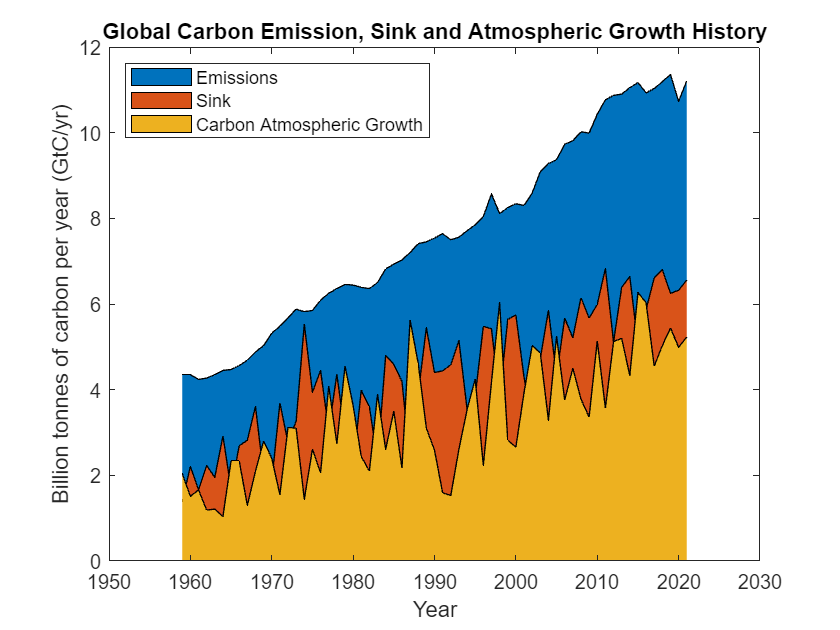

figure
% Create area of selected data
area(year_gcb,emissions,"DisplayName","Emissions");

hold on
% Create area of selected data
area(year_gcb,sink,"DisplayName","Sink");
% Create area of selected data
area(year_gcb,atmos_growth,"DisplayName","Carbon Atmospheric Growth ");
hold off
title("Global Carbon Emission, Sink and Atmospheric Growth History");

legend(Location="northwest");
ylabel("Billion tonnes of carbon per year (GtC/yr)");
xlabel("Year");

### Time Series Stationary Test

We perform the Augmented Dickey-Fuller (ADF) test on stationarity of time series. The ADF test for a unit root assesses the null hypothesis of a unit root in the time series. A test that fails to reject the null hypothesis, fails to reject the possibility of a unit root. It means that the series is non-stationary, may have a time trend.

**Result** **Table**:


$$\matrix{
\textbf{Country} & \textbf{Variable} & \textbf{ADF Stationary Result} \cr
US & CO_2 & \text{$\mathrm{Not}\;\text{Stationary}$} \cr
US & \Delta \mathrm{CO_2} & \text{Stationary} \cr
UK & CO_2 & \text{$\mathrm{Not}\;\text{Stationary}$} \cr
UK & \Delta \mathrm{CO_2} & \text{Stationary} \cr
Japan & CO2 & \text{$\mathrm{Not}\;\mathrm{Stationary}$} \cr
Japan & \Delta \mathrm{CO2} & \text{Stationary} \cr
}$$



$$\matrix{
\textbf{Country} & \textbf{Variable} & \textbf{ADF Stationary Result} \cr
US & Population& \text{$\mathrm{Not}\;\mathrm{Stationary}$} \cr
US & \Delta \mathrm{Population} & \text{$\mathrm{Not}\;\mathrm{Stationary}$} \cr
US & \Delta^2 \mathrm{Population} & \mathrm{Stationary} \cr
UK & Population& \text{$\mathrm{Not}\;\mathrm{Stationary}$} \cr
UK & \Delta \mathrm{Population} & \text{$\mathrm{Not}\;\mathrm{Stationary}$} \cr
UK & \Delta^2 \mathrm{Population} & \mathrm{Stationary} \cr
Japan & Population& \text{$\mathrm{Not}\;\mathrm{Stationary}$} \cr
Japan & \Delta \mathrm{Population} & \text{$\mathrm{Not}\;\mathrm{Stationary}$} \cr
Japan & \Delta^2 \mathrm{Population} & \mathrm{Stationary} \cr
}$$



$$\matrix{
\textbf{Country} & \textbf{Variable} & \textbf{ADF Stationary Result} \cr
US & GDP& \text{$\mathrm{Not}\;\mathrm{Stationary}$} \cr
US & \Delta \mathrm{GDP} & \text{Stationary} \cr
UK & GDP& \text{$\mathrm{Not}\;\mathrm{Stationary}$} \cr
UK & \Delta \mathrm{GDP} &  \text{Stationary} \cr
Japan & GDP& \text{$\mathrm{Not}\;\mathrm{Stationary}$} \cr
Japan & \Delta \mathrm{GDP} &  \text{Stationary} \cr
}$$


From the table above, we find that all CO2 variables are stationary after the first-order difference. All population variables are stationary after the second-order difference. All test reject the null hypothesis.

**Code here:**

**US**

[ADF_US, US_pvalue, US_stat, US_cvalue]= adftest(US_CO2); %non-stationary for original data
[ADF_US, US_pvalue, US_stat, US_cvalue]= adftest(diff(US_CO2)); %stationary after first-order test
[ADF_US, US_pvalue, US_stat, US_cvalue]= adftest(US_population); %non-stationary for original data
[ADF_US, US_pvalue, US_stat, US_cvalue]= adftest(diff(US_population));%non-stationary after first-order test
[ADF_US, US_pvalue, US_stat, US_cvalue]= adftest(diff(diff(US_population)));%stationary after second-order test
[ADF_US, US_pvalue, US_stat, US_cvalue]= adftest(US_GDP);%non-stationary for original data
[ADF_US, US_pvalue, US_stat, US_cvalue]= adftest(diff(US_GDP));%stationary after first-order test

**UK**

[ADF_UK, UK_pvalue, UK_stat, UK_cvalue] = adftest(UK_CO2);
[ADF_UK, UK_pvalue, UK_stat, UK_cvalue] = adftest(diff(UK_CO2));%stationary after first-order test
[ADF_UK, UK_pvalue, UK_stat, UK_cvalue] = adftest(UK_population);
[ADF_UK, UK_pvalue, UK_stat, UK_cvalue] = adftest(diff(UK_population));%non-stationary after first-order
[ADF_UK, UK_pvalue, UK_stat, UK_cvalue] = adftest(diff(diff(UK_population)));% stationary after second-order
[ADF_UK, UK_pvalue, UK_stat, UK_cvalue] = adftest(UK_GDP);
[ADF_UK, UK_pvalue, UK_stat, UK_cvalue] = adftest(diff(UK_GDP));% stationary after first-order

**JAPAN**

[ADF_JAPAN, JAPAN_pvalue, JAPAN_stat, JAPAN_cvalue] = adftest(JAPAN_CO2);
[ADF_JAPAN, JAPAN_pvalue, JAPAN_stat, JAPAN_cvalue] = adftest(diff(JAPAN_CO2)); %stationary after first-order diff
[ADF_JAPAN, JAPAN_pvalue, JAPAN_stat, JAPAN_cvalue] = adftest(JAPAN_population);
[ADF_JAPAN, JAPAN_pvalue, JAPAN_stat, JAPAN_cvalue] = adftest(diff(JAPAN_population));
[ADF_JAPAN, JAPAN_pvalue, JAPAN_stat, JAPAN_cvalue] = adftest(diff(diff(JAPAN_population))); %stationary after second-order diff
[ADF_JAPAN, JAPAN_pvalue, JAPAN_stat, JAPAN_cvalue] = adftest(JAPAN_GDP);
[ADF_JAPAN, JAPAN_pvalue, JAPAN_stat, JAPAN_cvalue] = adftest(diff(JAPAN_GDP)); %stationary after first-order diff

## TVP-VAR model and Path Simulation

TVP-VAR (Time-varying parameter VAR) is a statistical model used in econometrics that extends the traditional VAR model by allowing the parameters to vary over time. It is useful when analyzing economic variables that exhibit time-varying relationships due to structural changes, shifts in policymaking, evolution in technologies, and other factors. 

Therefore, the TVP-VAR model is a good fit for carbon emission simulation by adapting to energy flucturation caused by pandemic and Ukraine crisis. By allowing the parameters to adapt to each period, TVP-VAR provides more accurate forecasts and analysis of the underlying relationships between variables. 

**In the following steps, I choose nlag=4 (bigger than current optimal point nlag = 3) because:**

- The optimal point for single and multiple countries requires AIC to be 3 at most

- In practice we need a larger nlag to represent the dynamic behaviour

**We determine the nlag parameters in TVP-VAR to be 4, for US, UK, Japan and China. **

asvar = {'GDP', 'CO2'};

### Determine nlag with AIC before modelling

First, I checked AIC information criteria for single country and multiple countries in VAR models. The AIC reached optimal point at nlag = 1, 2 or 3 for different countries with MATLAB aicbic() function.

Pre-setting Code:

Mdl(1)=varm(1,1); 
Mdl(2)=varm(1,2);
Mdl(3)=varm(1,3);
Mdl(4)=varm(1,4);

numMdl = numel(Mdl);
logL = zeros(numMdl,1);      % Preallocate
numParam = zeros(numMdl,1);
numObs = zeros(numMdl,1);


**Single Country: US optimized at nlag=3**

y=diff(US_CO2);
[aic]=aic_for_nlag(y,Mdl,numMdl,logL,numParam,numObs);
[~,minIdx] = min(aic);
disp("Accoring to AIC, the optimal model for US is "+Mdl(minIdx).Description)

Accoring to AIC, the optimal model for US is 1-Dimensional VAR(3) Model


**Single Country: UK optimized at nlag=1**

y=diff(UK_CO2);
[aic]=aic_for_nlag(y,Mdl,numMdl,logL,numParam,numObs);
[~,minIdx] = min(aic);
disp("Accoring to AIC, the optimal model for UK is "+Mdl(minIdx).Description)

Accoring to AIC, the optimal model for UK is 1-Dimensional VAR(1) Model


**Single Country: Japan optimized at nlag=1**

y=diff(JAPAN_CO2);
[aic]=aic_for_nlag(y,Mdl,numMdl,logL,numParam,numObs);
[~,minIdx] = min(aic);
disp("Accoring to AIC, the optimal model for Japan is "+Mdl(minIdx).Description)

Accoring to AIC, the optimal model for Japan is 1-Dimensional VAR(1) Model


**Single Country: China optimized at nlag=2**

y=diff(CHINA_CO2);
[aic]=aic_for_nlag(y,Mdl,numMdl,logL,numParam,numObs);
[~,minIdx] = min(aic);
disp("Accoring to AIC, the optimal model for China is "+Mdl(minIdx).Description)

Accoring to AIC, the optimal model for China is 1-Dimensional VAR(2) Model


**Multiple Countries: for 4 countries, AIC optimized at nlag=1**

Take interactions among 4 countries into models and compute new AIC

Mdl(1)=varm(4,1);
Mdl(2)=varm(4,2);
Mdl(3)=varm(4,3);
Mdl(4)=varm(4,4);

numMdl = numel(Mdl);
logL = zeros(numMdl,1);      % Preallocate
numParam = zeros(numMdl,1);
numObs = zeros(numMdl,1);

y=[diff(US_CO2),diff(UK_CO2),diff(JAPAN_CO2),diff(CHINA_CO2)];
for j = 1:numMdl
    y0 = y(1:Mdl(j).P,:);             % Presample
    yest = y((Mdl(j).P+1):end,:);     % Estimation sample
    [EstMdl,~,logL(j)] = estimate(Mdl(j),yest,Y0=y0, ...
        Display="off");
    results = summarize(EstMdl);
    numParam(j) = results.NumEstimatedParameters;
    numObs(j) = results.SampleSize; 
end

aic=aicbic(logL,numParam,numObs,Normalize=true);
[~,minIdx] = min(aic);
disp("Accoring to AIC, the optimal model for US, UK, Japan and China together is "+Mdl(minIdx).Description)

Accoring to AIC, the optimal model for US, UK, Japan and China together is 4-Dimensional VAR(1) Model


### Carbon Neutrality Path Simulation

**We have set carbon emission target for 4 countries in 2050, **according to Copenhagen carbon neutrality target in 2025 and related research. Abiding these goals makes it possible to achieve carbon neutrality. We simulate the path by setting these targets. 

**US: 20% of its emission in 1990**

**UK: 20% of its emission in 1990**

**Japan: 20% of its emission in 1990**

**China: 50% of its emission in 2005**

According to my simulation, the possibility for each country meet their carbon neutrality are as follows. 

**US: 2.88%**

**UK: 4.23%**

**Japan: 2.89%**

**China: 0.25%**

**Carbon neutrality are very unlikely to be achieved without more efforts. **

% if isequal(exist('tvpvar_test.csv', 'file'), 2)
%   delete('tvpvar_test.csv');
% end
asvar = {'GDP', 'CO2'}; 

Simulation for US 

Result Table:

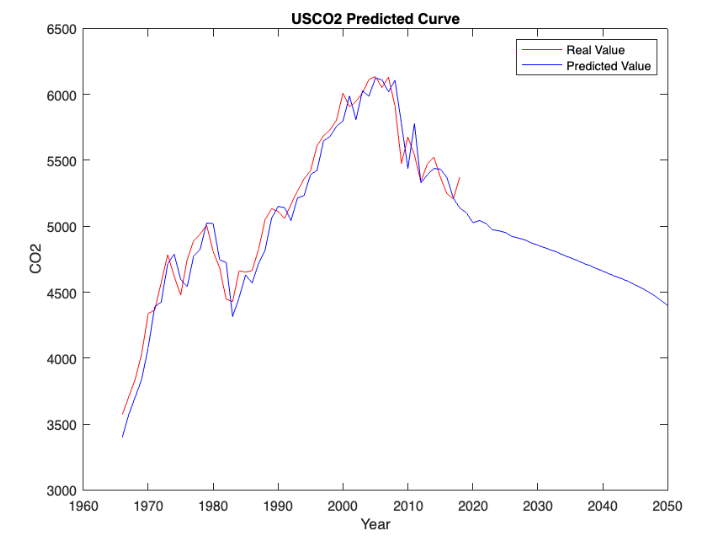

Code:


Iteration:
-1000 
0 
1000 
2000 
3000 
4000 
5000 
6000 
7000 
8000 
9000 
10000 


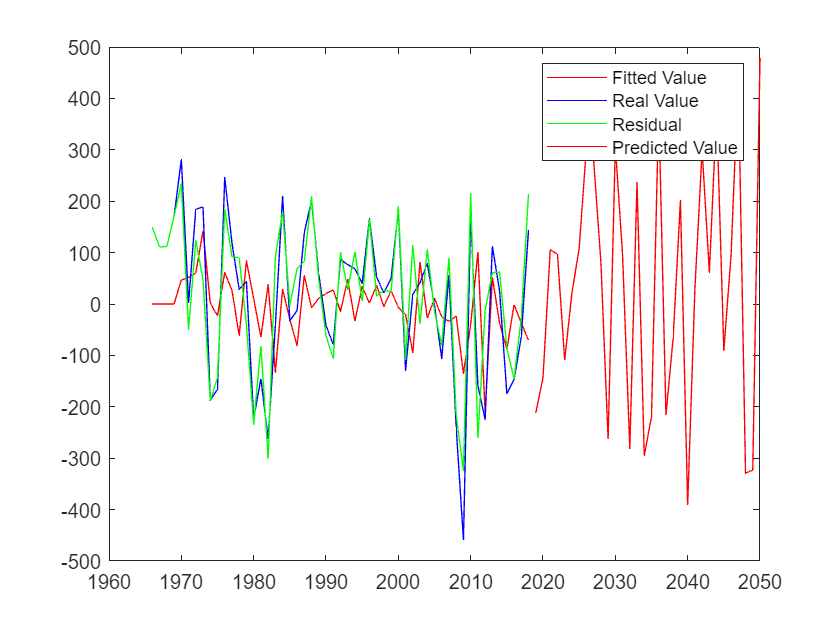

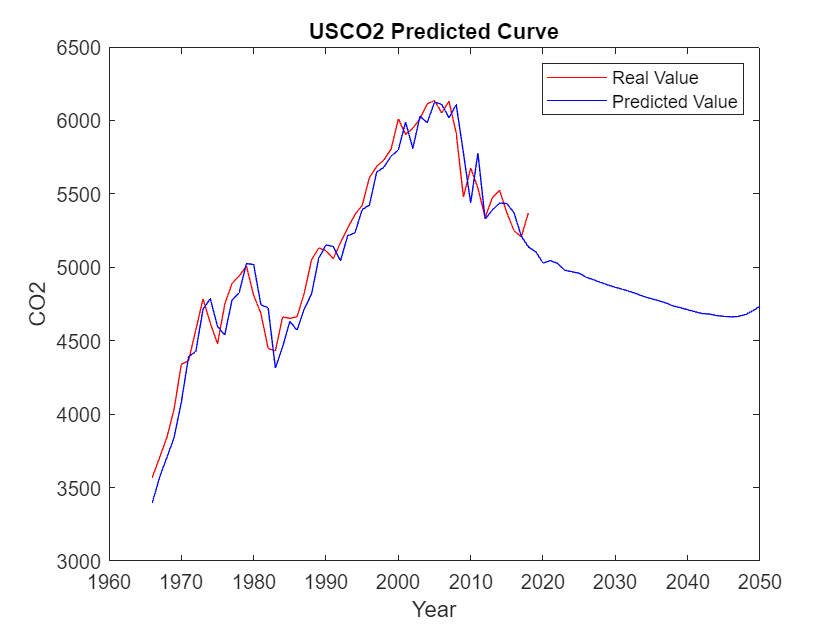

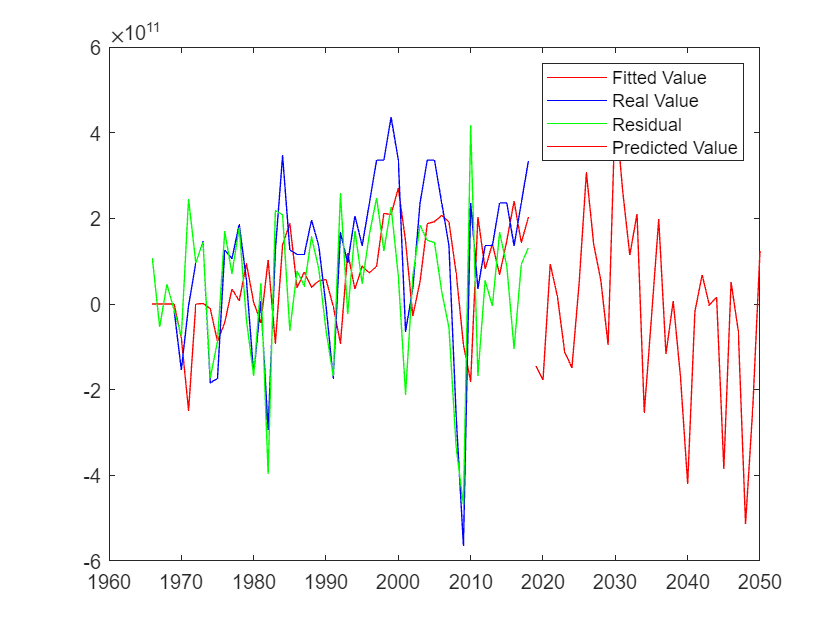

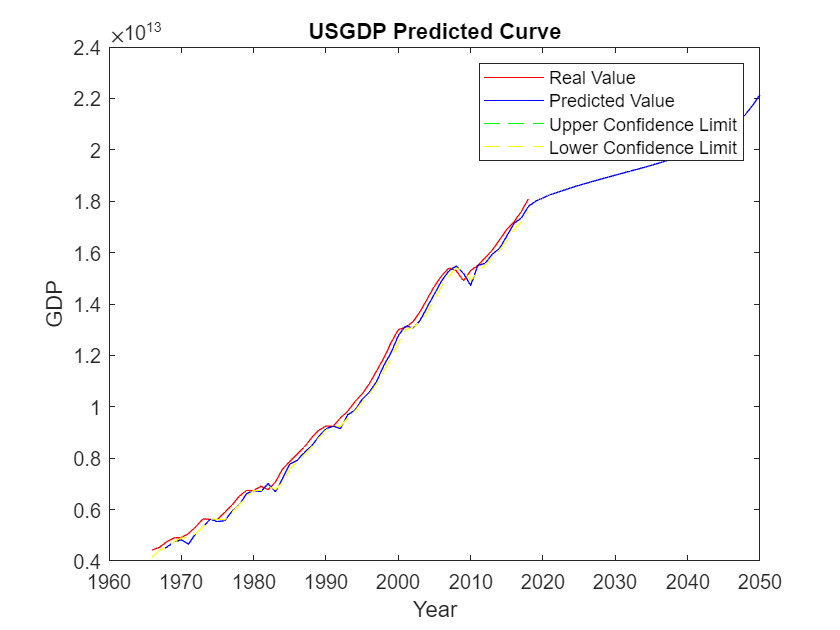



                        [ESTIMATION RESULT]
----------------------------------------------------------------------
Parameter   Mean      Stdev       95%U       95%L    Geweke     Inef.
----------------------------------------------------------------------
sigma_b1       0.0022     0.0003     0.0018     0.0028     0.564      3.23
sigma_b2       0.0022     0.0003     0.0018     0.0028     0.190      3.85
sigma_a1       0.0048     0.0012     0.0031     0.0077     0.024     23.13
sigma_h1       0.0049     0.0013     0.0032     0.0081     0.031     16.53
sigma_h2       0.0049     0.0013     0.0031     0.0080     0.094     16.22
----------------------------------------------------------------------
TVP-VAR model (Lag = 4)
Iteration: 10000
Sigma(b): Diagonal

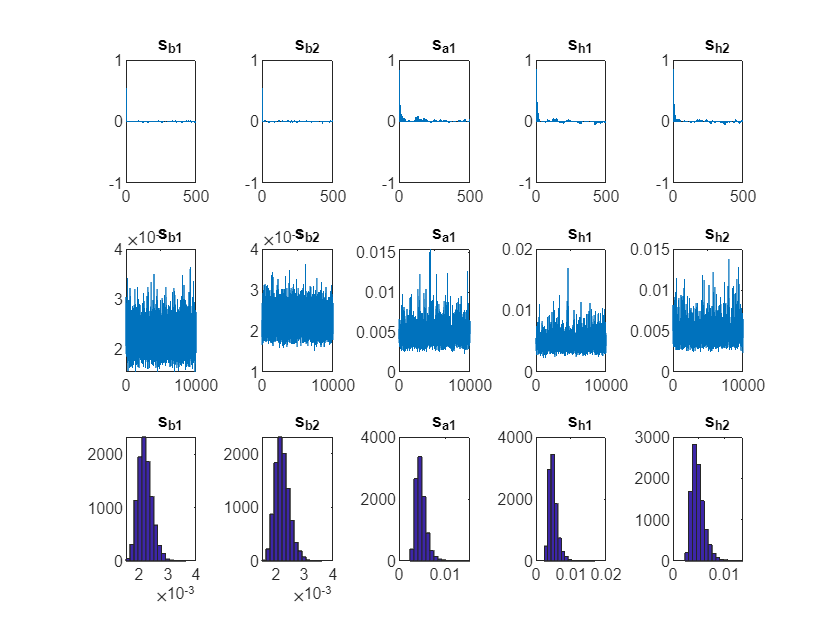

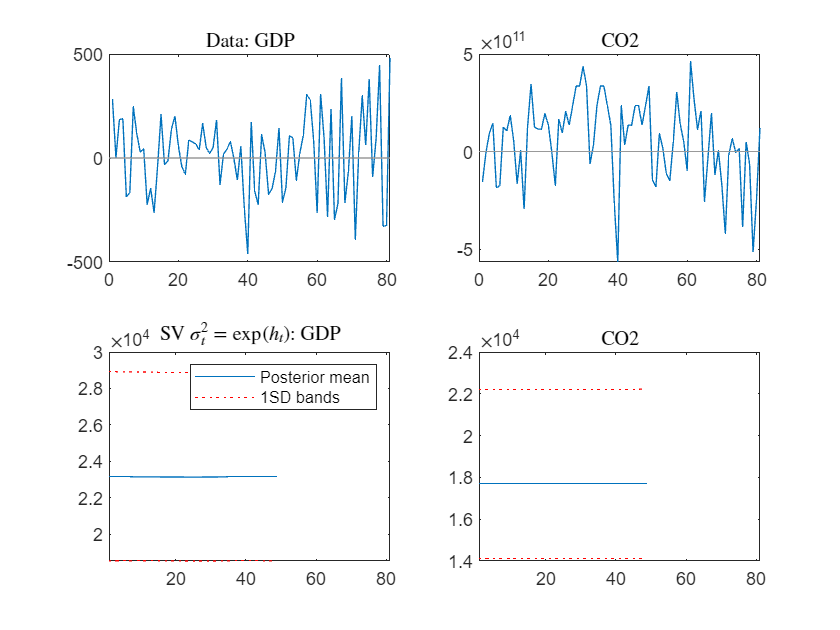

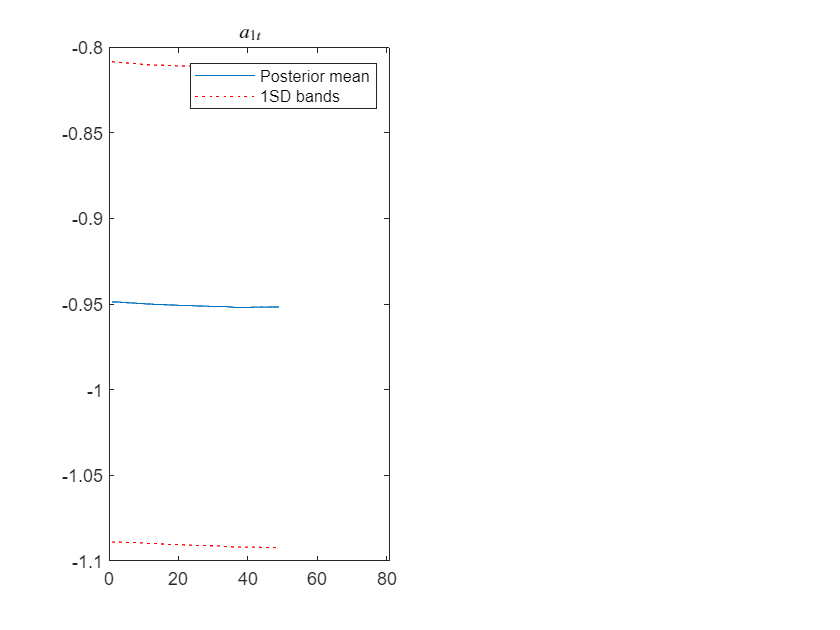

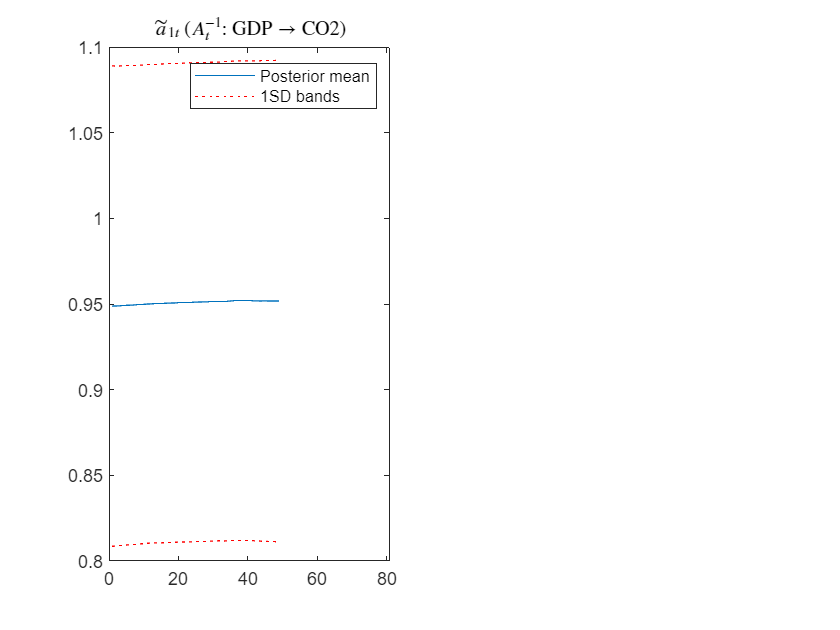



Ranseed: 1
Time: 97.60



% writematrix(US_data(1:end-2,:),'tvpvar_test.csv', ...
%  'Sheet', 'A1');
% writetable('tvpvar_test.xlsx', ...
%       US_data(1:end-2,:), 'Sheet1', 'A1');
% my = xlsread('tvpvar_test.xlsx');
% my = readtable('tvpvar_test.xlsx');
my=US_data(1:end-2,:);
nlag = 4;  %    
set_global_variables('data', my, asvar, nlag);  % set global output variable
set_global_variables('fastimp', 1);  % fast computing of response
[USCO2, USGDP] = mote_carlo_simulation(10000, US_CO2,US_GDP, 0);  %mote-carlo simulation for 10000 times

Path to US Carbon Neutrality Target: **ONLY 2.88 % success rate**


Iteration:
-1000 
0 
1000 
2000 
3000 
4000 
5000 
6000 
7000 
8000 
9000 
10000 


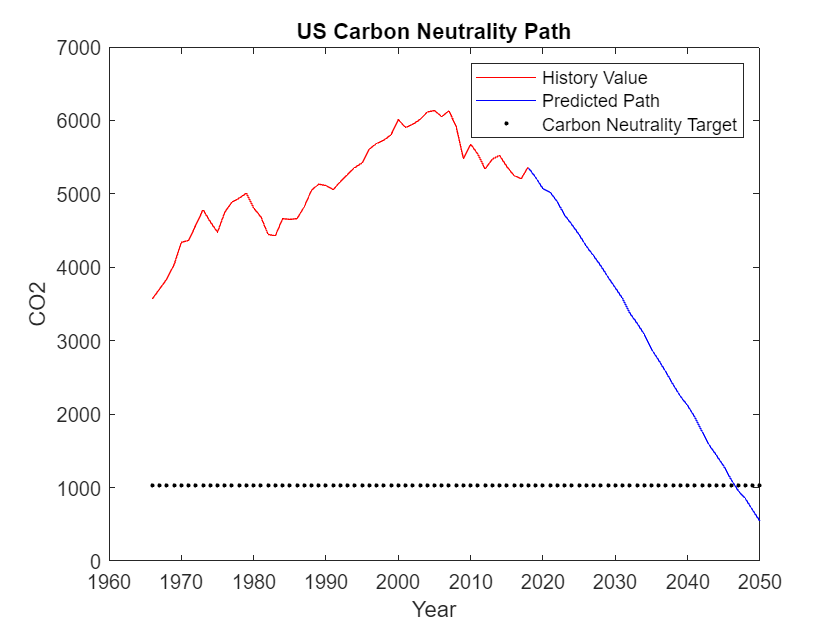

The probability to achieve neutrality goal：0.0276


my = US_data(1:end-2,:);
nlag = 4;  
set_global_variables('data', my, asvar, nlag);  % set variables
set_global_variables('fastimp', 1);  % fast computing of response
[USCO2, USGDP] = carbon_neutrality_path(10000, US_CO2,US_GDP, 0);  %path simulation(with US target set in function）

Simulation for UK

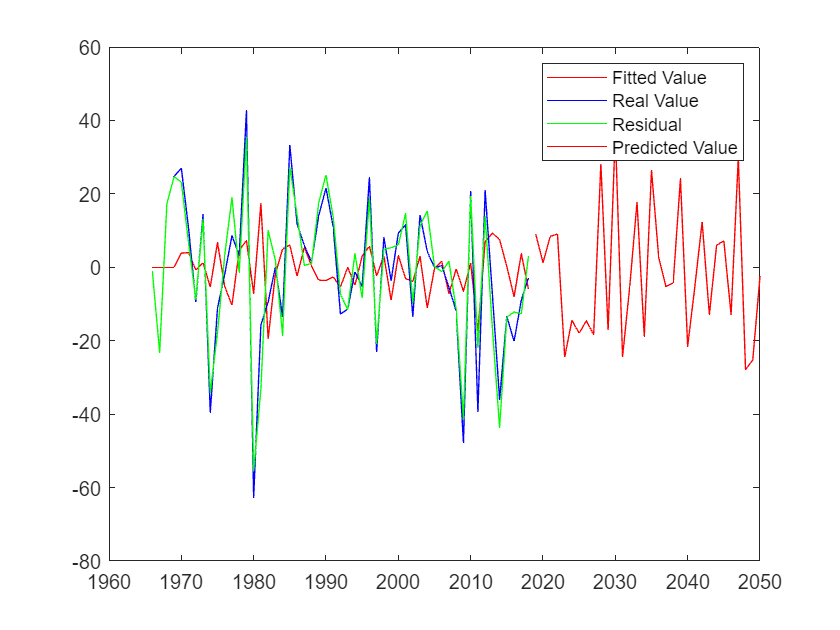


Iteration:
-1000 
0 
1000 
2000 
3000 
4000 
5000 
6000 
7000 
8000 
9000 
10000 


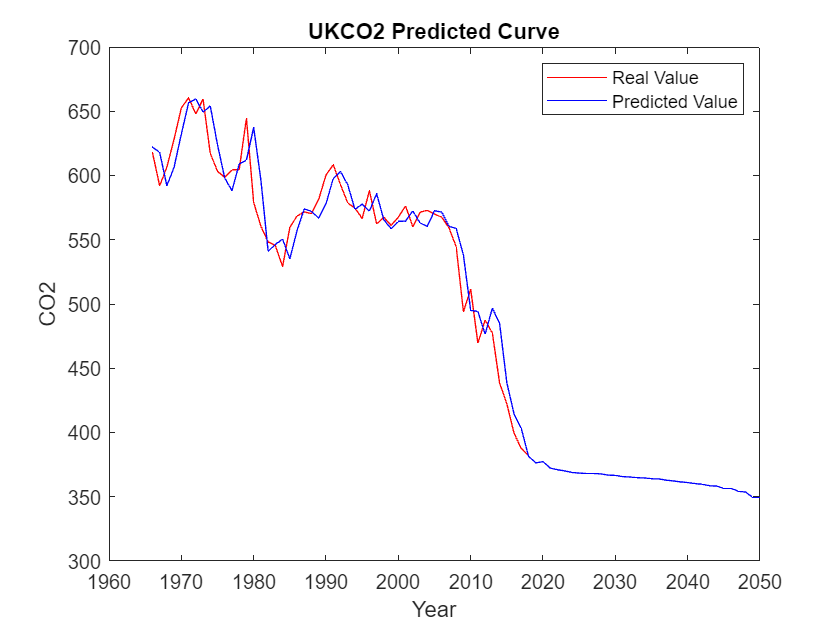

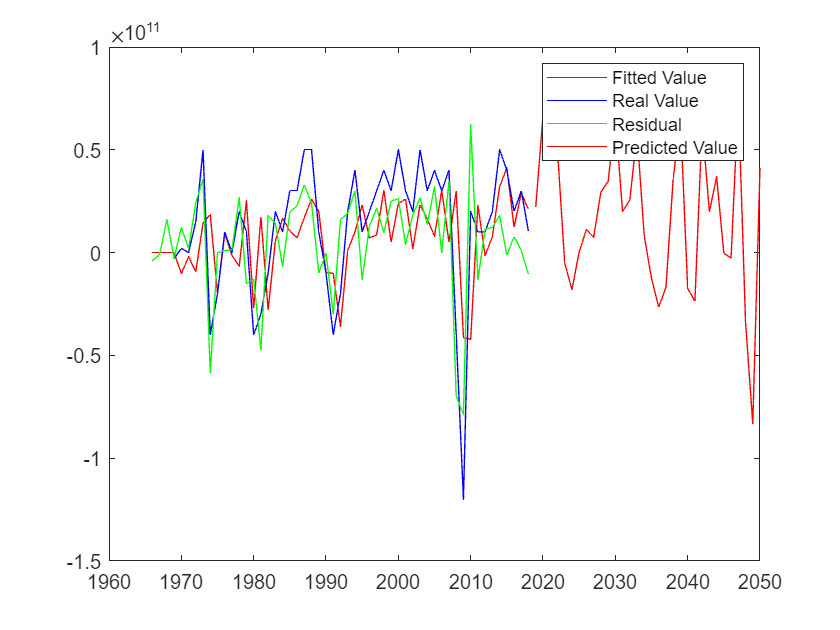

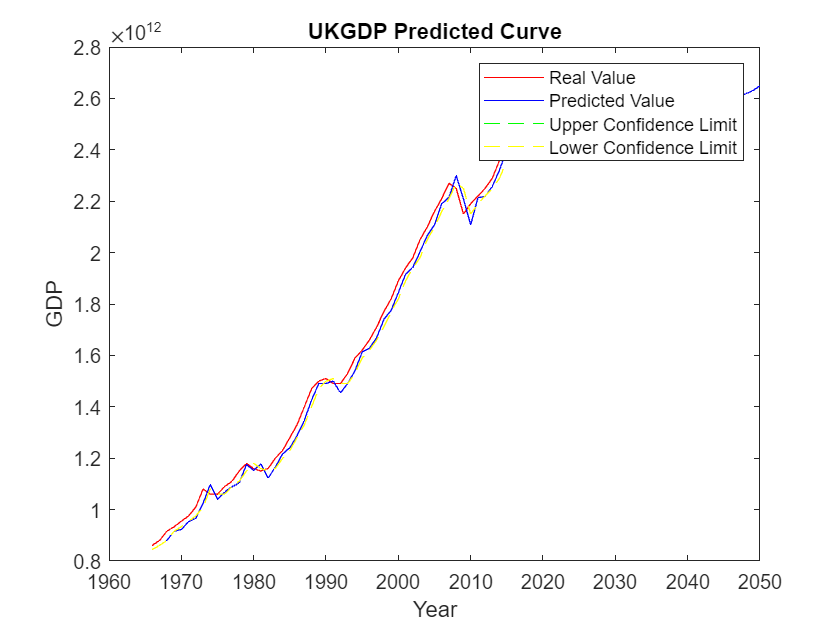



                        [ESTIMATION RESULT]
----------------------------------------------------------------------
Parameter   Mean      Stdev       95%U       95%L    Geweke     Inef.
----------------------------------------------------------------------
sigma_b1       0.0022     0.0001     0.0020     0.0025     0.125      1.10
sigma_b2       0.0022     0.0001     0.0020     0.0025     0.056      1.53
sigma_a1       0.0048     0.0011     0.0032     0.0075     0.606     12.59
sigma_h1       0.0048     0.0011     0.0031     0.0075     0.605     10.44
sigma_h2       0.0048     0.0012     0.0031     0.0078     0.405     14.37
----------------------------------------------------------------------
TVP-VAR model (Lag = 4)
Iteration: 10000
Sigma(b): Diagonal

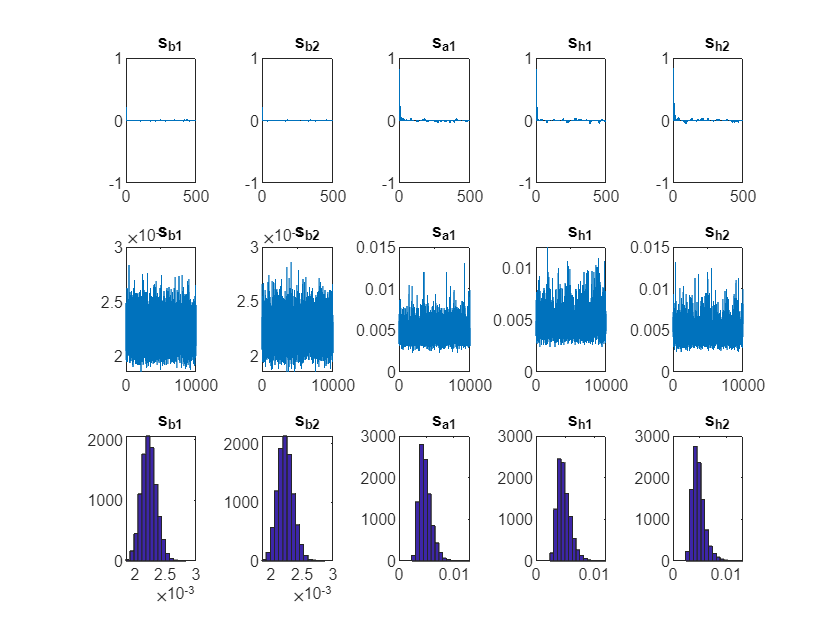

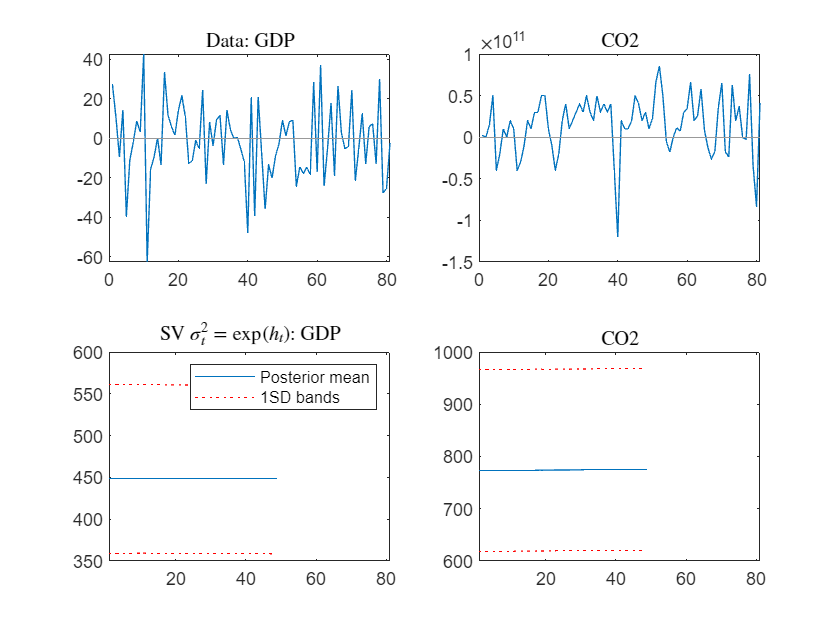

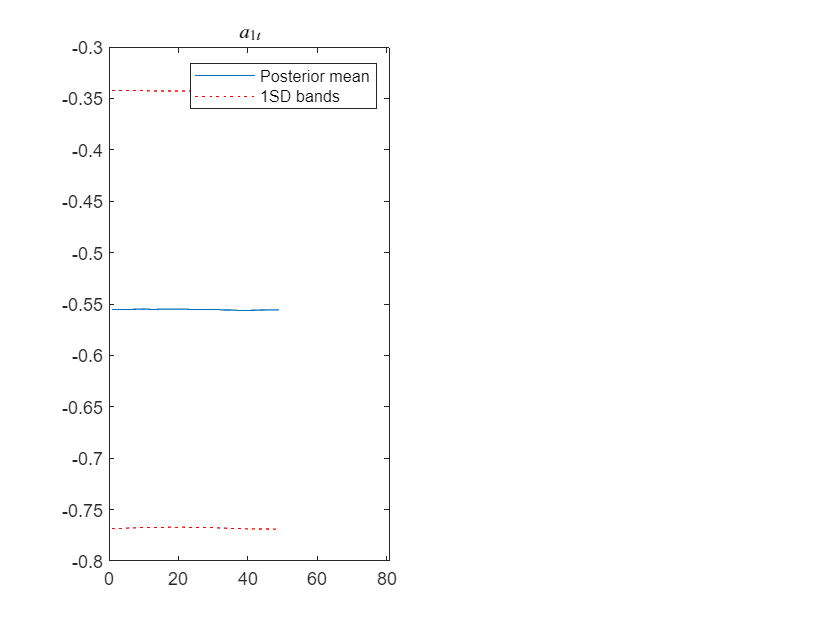

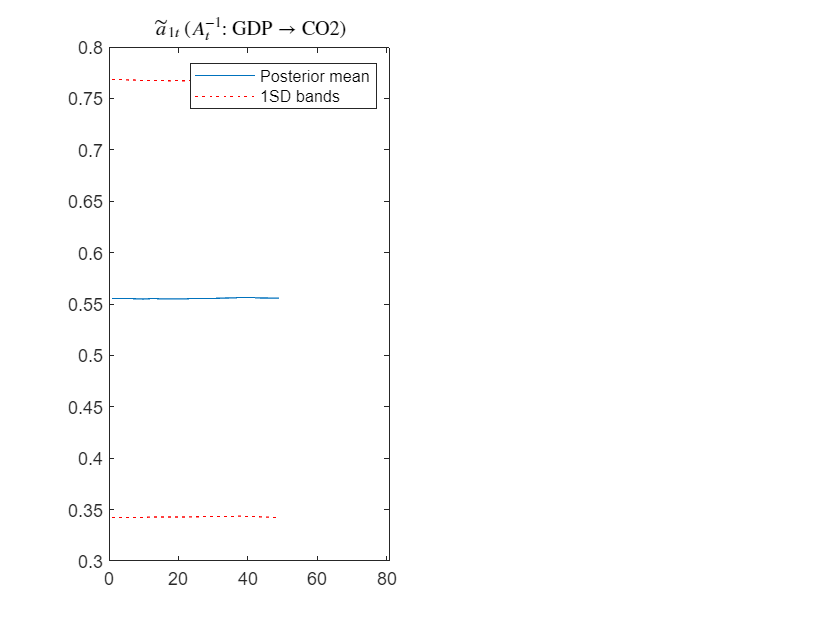



Ranseed: 1
Time: 97.99



figure()
my = UK_data(1:end-2,:);
nlag = 4;  
set_global_variables('data', my, asvar, nlag); 
set_global_variables('fastimp', 1);  % fast computing of response
[UKCO2, UKGDP] = mote_carlo_simulation(10000, UK_CO2, UK_GDP, 1);  %Target set

Path to UK Carbon Neutrality Target: **ONLY 4.23 % success rate**


Iteration:
-1000 
0 
1000 
2000 
3000 
4000 
5000 
6000 
7000 
8000 
9000 
10000 


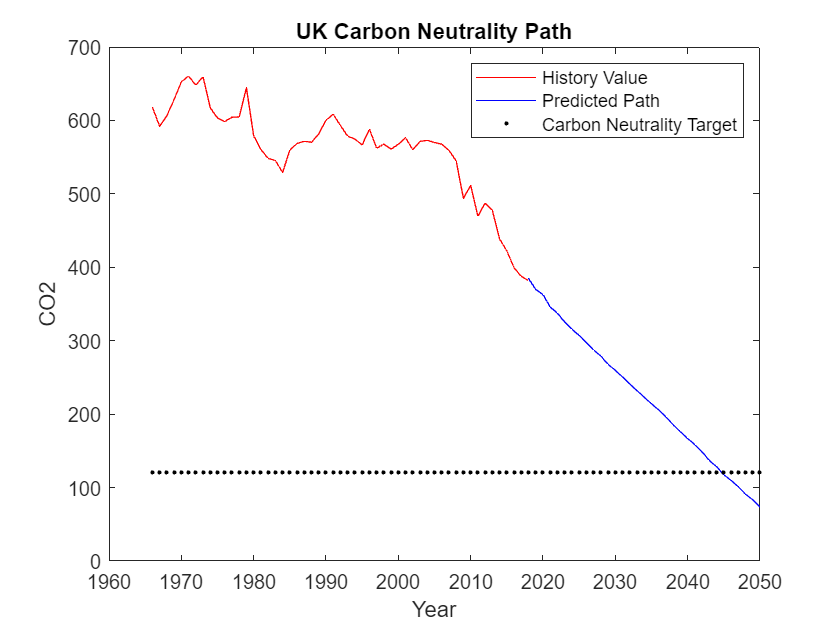

The probability to achieve neutrality goal：0.0415


figure()
my = UK_data(1:end-2,:);
nlag = 4;  
set_global_variables('data', my, asvar, nlag);  
set_global_variables('fastimp', 1);  % fast computing of response
[UKCO2, UKGDP] = carbon_neutrality_path(10000, UK_CO2, UK_GDP, 1);  

Simulation for Japan

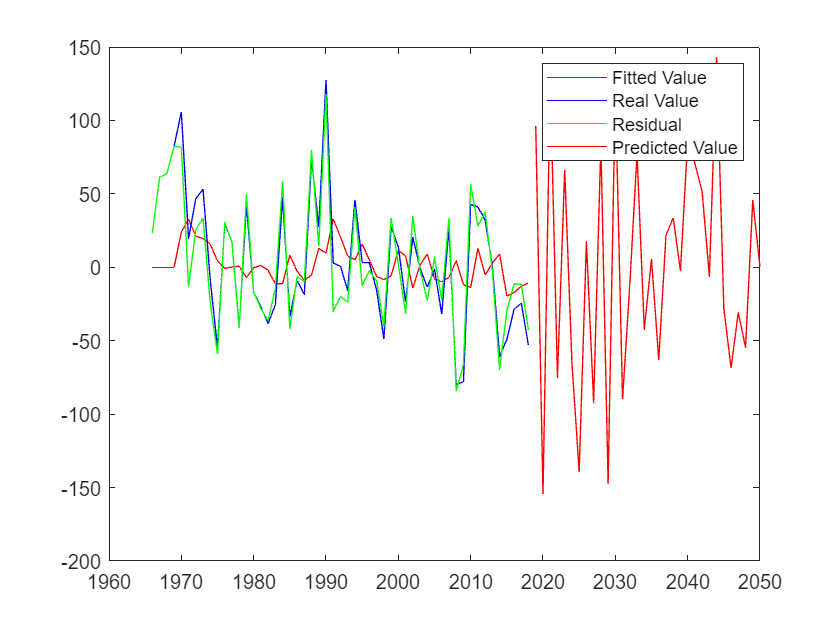


Iteration:
-1000 
0 
1000 
2000 
3000 
4000 
5000 
6000 
7000 
8000 
9000 
10000 


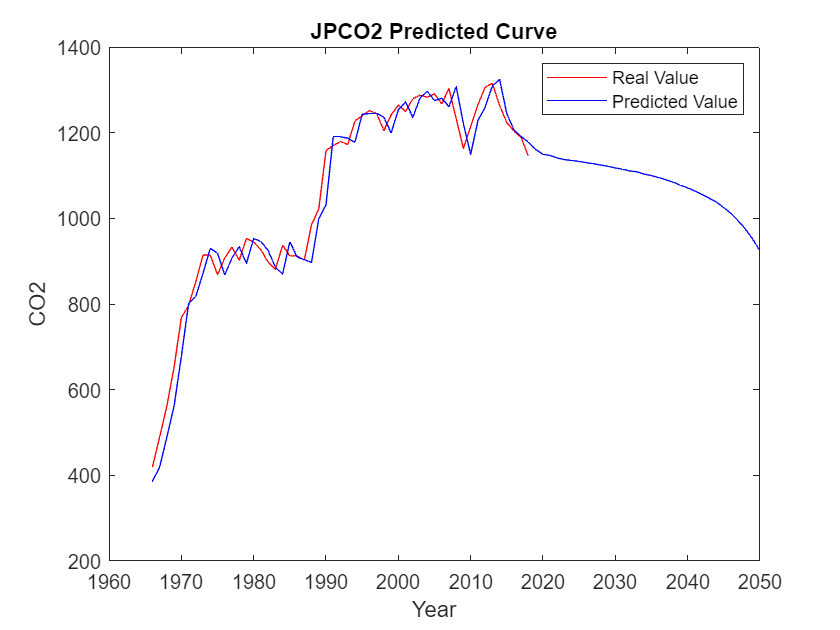

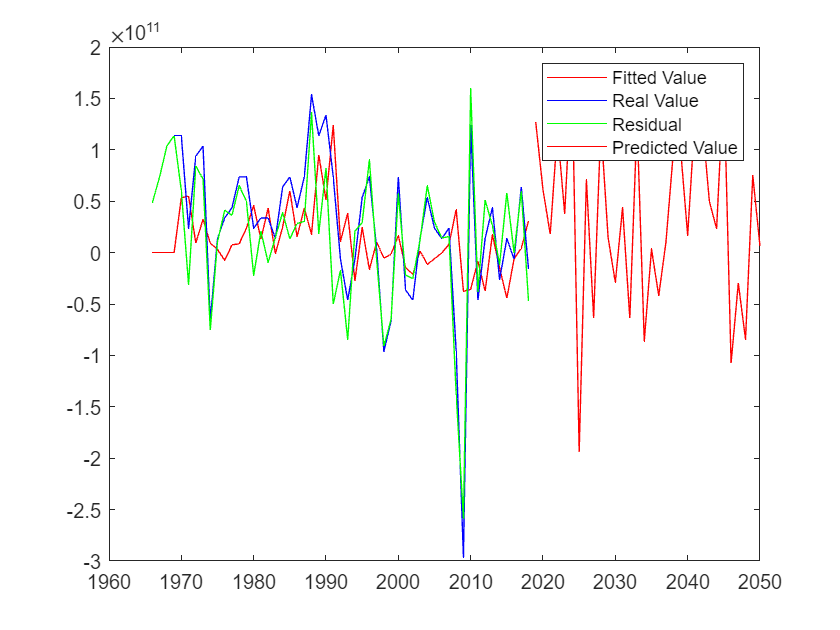

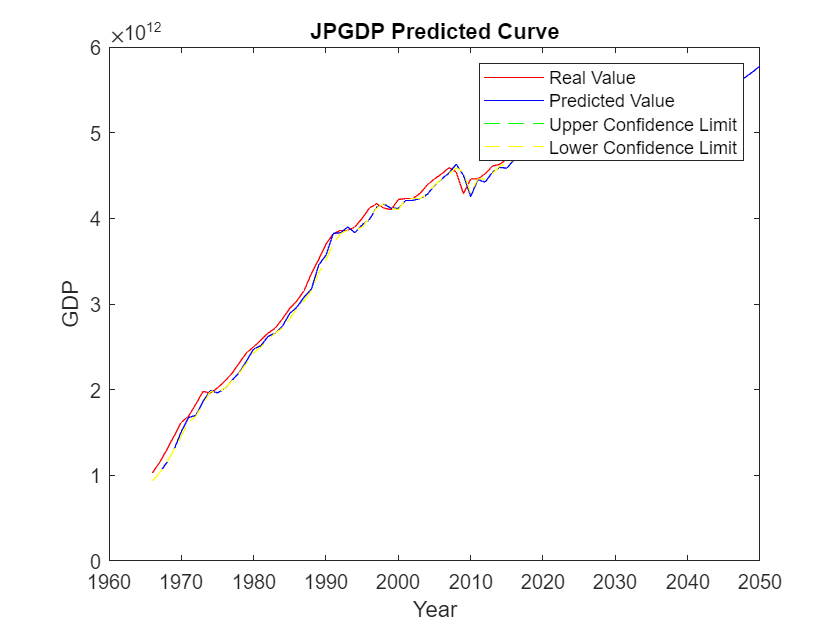



                        [ESTIMATION RESULT]
----------------------------------------------------------------------
Parameter   Mean      Stdev       95%U       95%L    Geweke     Inef.
----------------------------------------------------------------------
sigma_b1       0.0022     0.0001     0.0021     0.0024     0.197      1.10
sigma_b2       0.0022     0.0001     0.0021     0.0024     0.936      0.53
sigma_a1       0.0049     0.0013     0.0031     0.0083     0.739     11.98
sigma_h1       0.0048     0.0012     0.0031     0.0077     0.559     10.29
sigma_h2       0.0049     0.0013     0.0031     0.0080     0.436     12.56
----------------------------------------------------------------------
TVP-VAR model (Lag = 4)
Iteration: 10000
Sigma(b): Diagonal

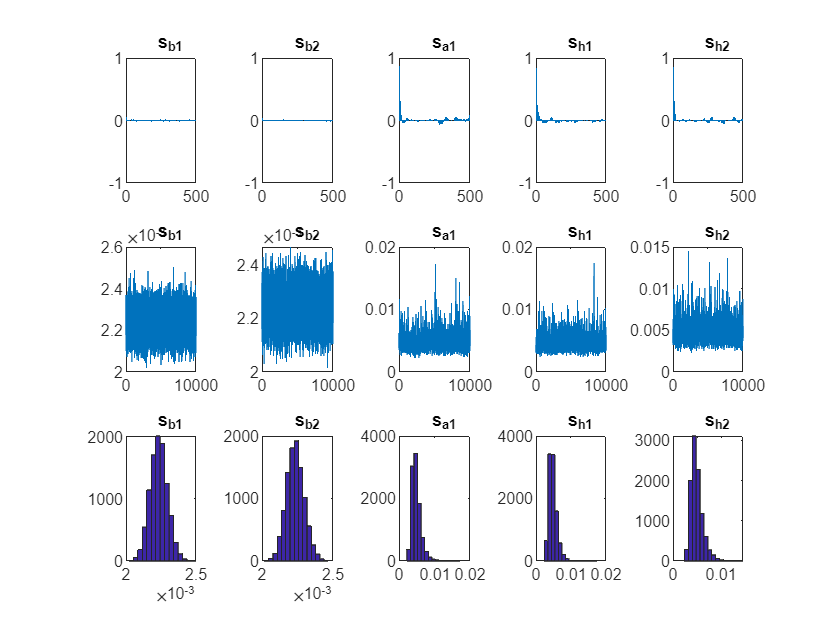

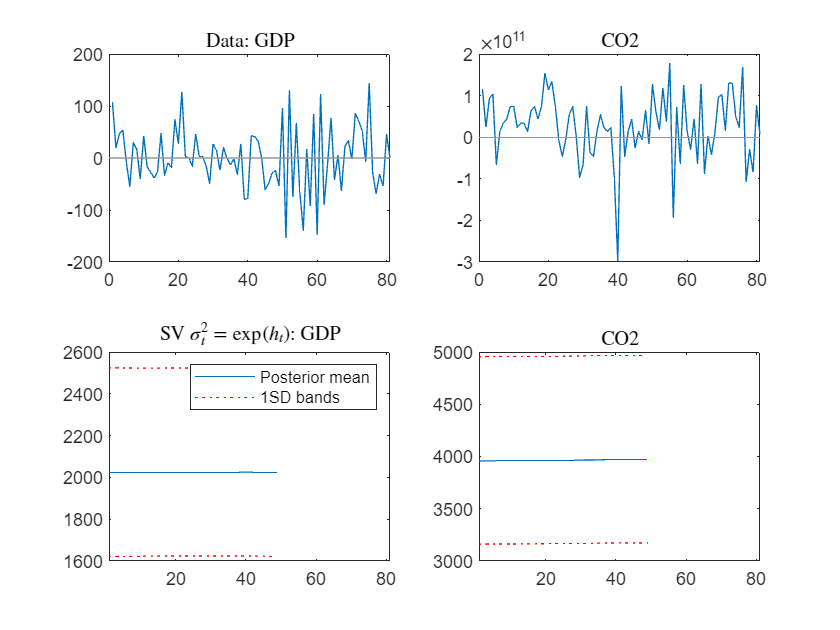

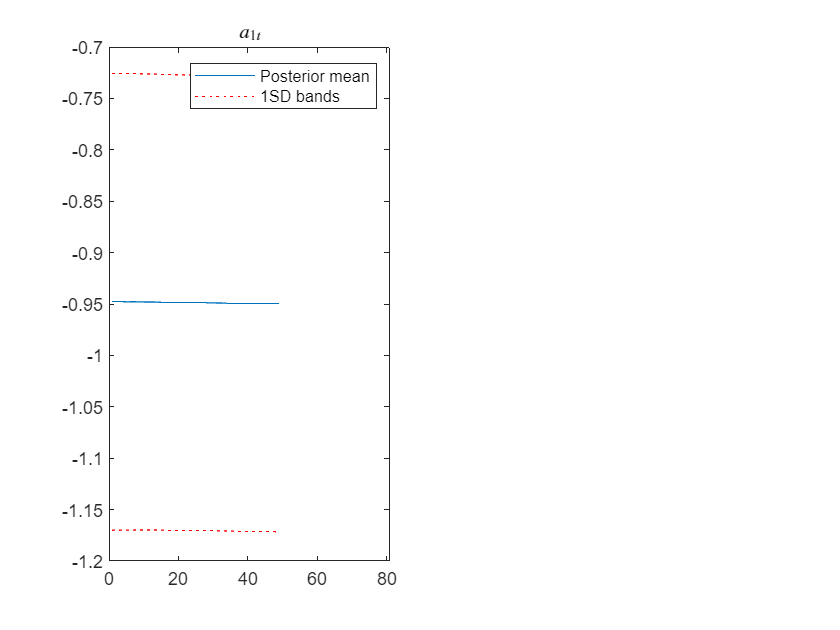

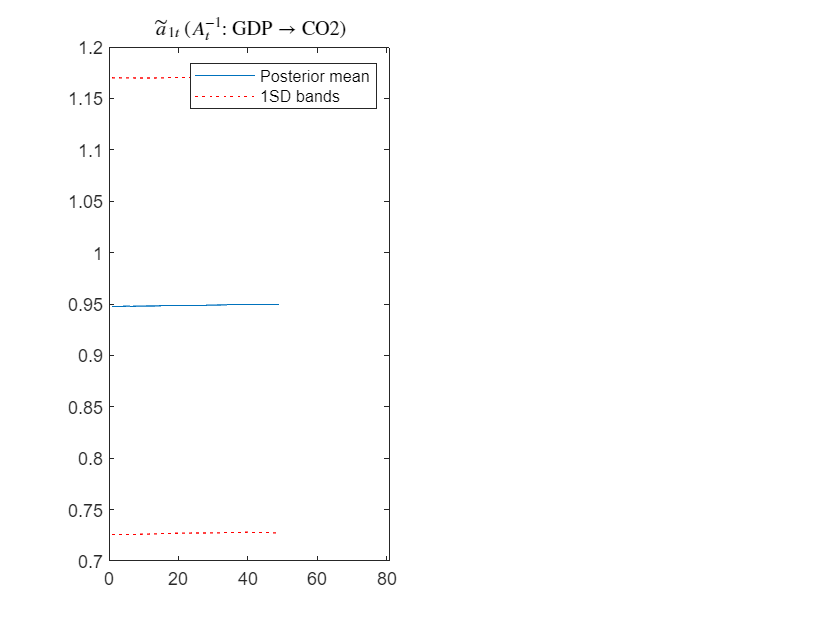



Ranseed: 1
Time: 99.88



figure()
% xlswrite('tvpvar_test.xlsx', JAPAN_data(1:end-2,:), 'Sheet1', 'A1');
my = JAPAN_data(1:end-2,:);
nlag = 4;  
set_global_variables('data', my, asvar, nlag); 
set_global_variables('fastimp', 1);  % fast computing of response
[JAPANCO2, JAPANGDP] = mote_carlo_simulation(10000, JAPAN_CO2, JAPAN_GDP, 2);  

Path to Japan Carbon Neutrality Target: **ONLY 2.89 % success rate**


Iteration:
-1000 
0 
1000 
2000 
3000 
4000 
5000 
6000 
7000 
8000 
9000 
10000 


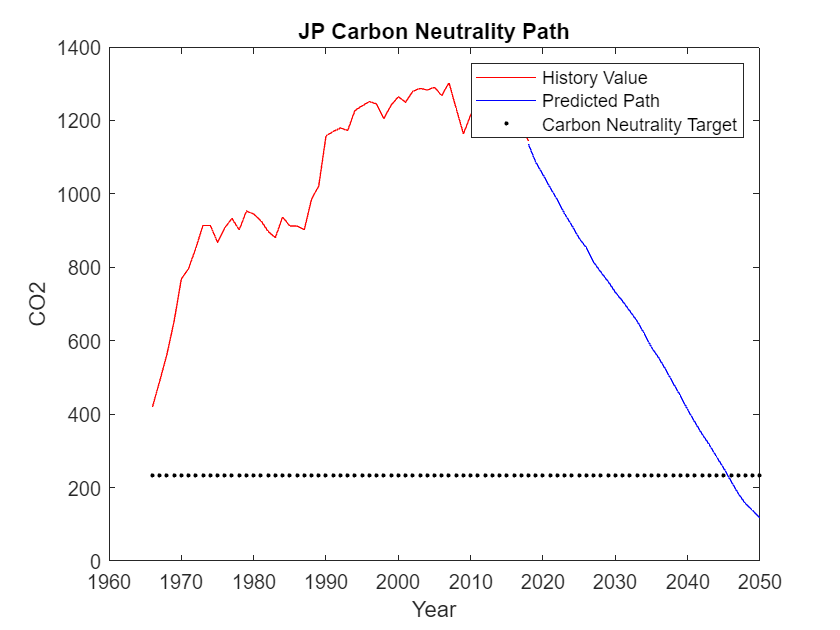

The probability to achieve neutrality goal：0.0326


figure()
% xlswrite('tvpvar_test.xlsx', JAPAN_data(1:end-2,:), 'Sheet1', 'A1');
my = JAPAN_data(1:end-2,:);
nlag = 4; 
set_global_variables('data', my, asvar, nlag);
set_global_variables('fastimp', 1);  % fast computing of response
[JAPANCO2, JAPANGDP] = carbon_neutrality_path(10000, JAPAN_CO2, JAPAN_GDP, 2);  %Target set

Simulation for China

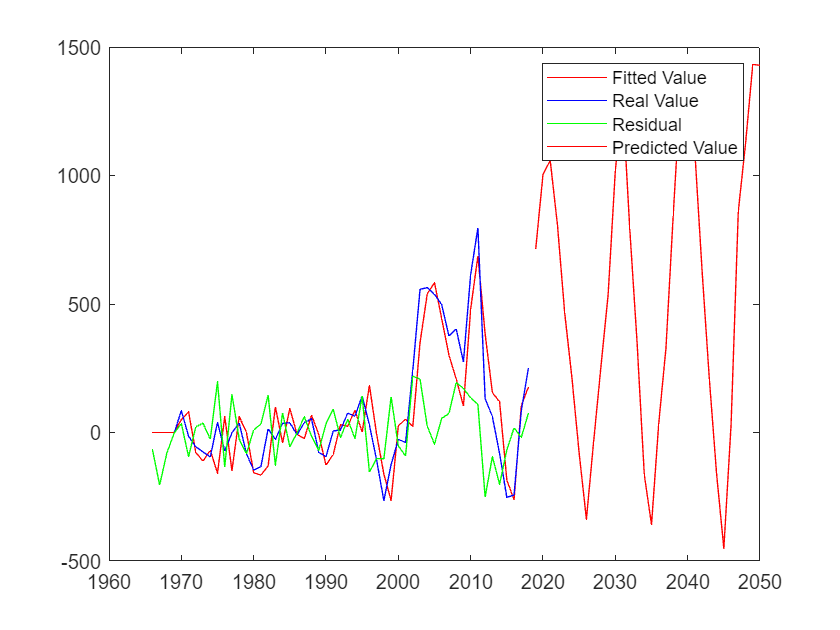


Iteration:
-1000 
0 
1000 
2000 
3000 
4000 
5000 
6000 
7000 
8000 
9000 
10000 


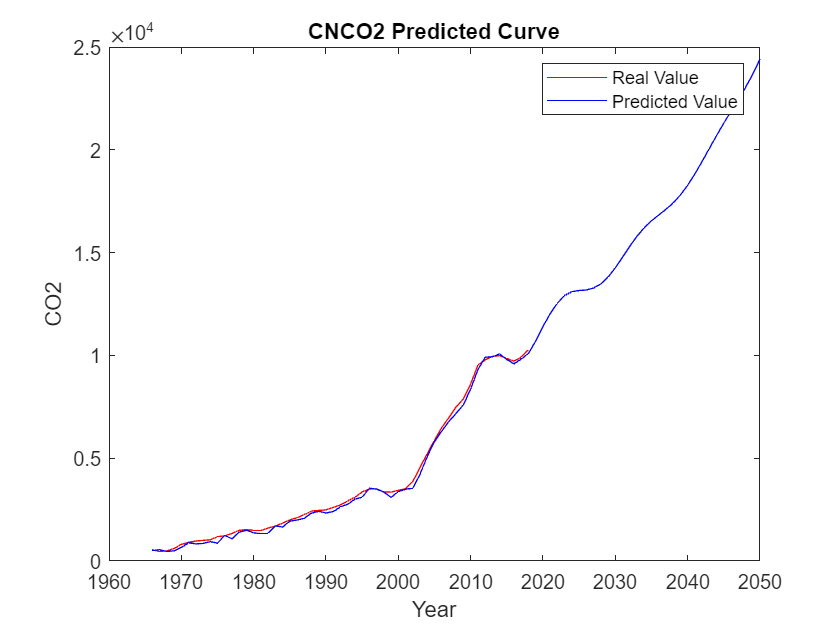

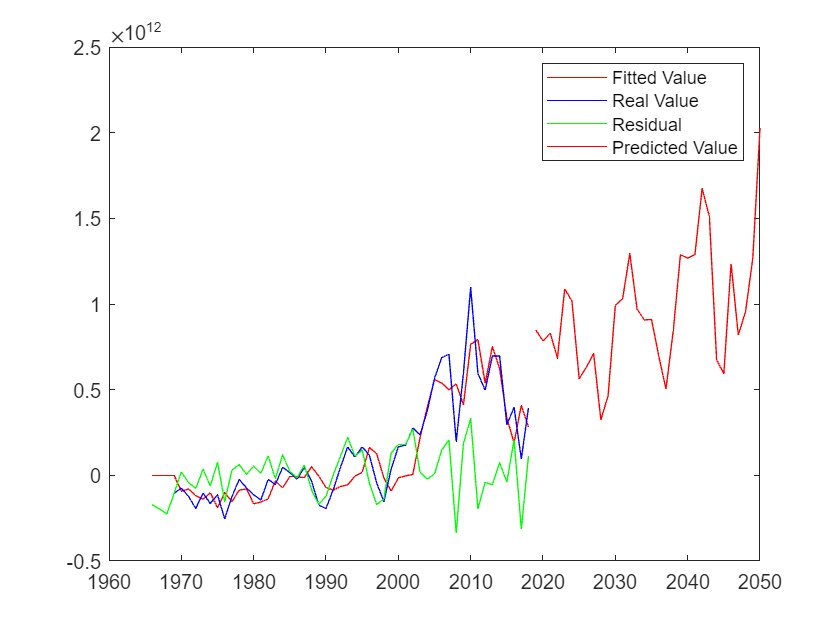

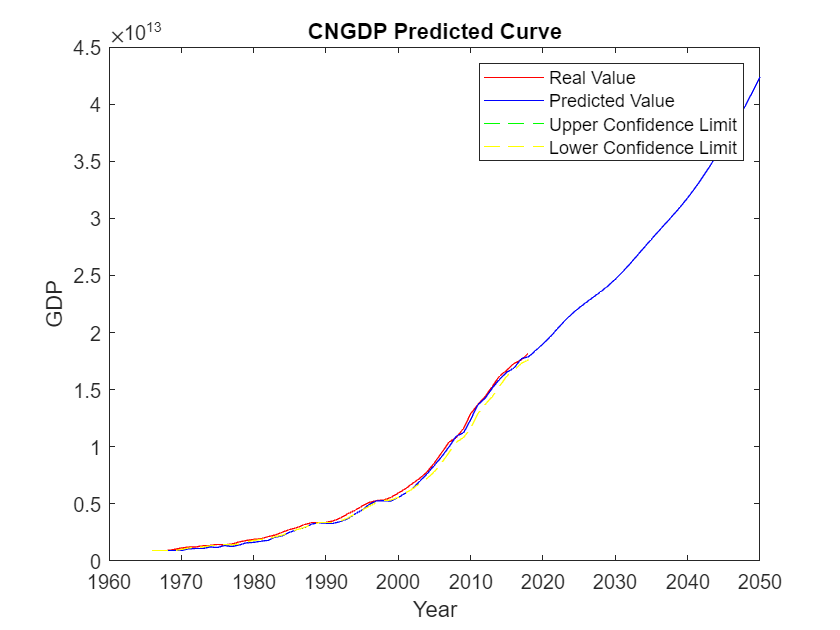



                        [ESTIMATION RESULT]
----------------------------------------------------------------------
Parameter   Mean      Stdev       95%U       95%L    Geweke     Inef.
----------------------------------------------------------------------
sigma_b1       0.0022     0.0000     0.0022     0.0023     0.163      1.06
sigma_b2       0.0022     0.0000     0.0022     0.0023     0.389      0.69
sigma_a1       0.0048     0.0012     0.0031     0.0077     0.027     13.01
sigma_h1       0.0048     0.0012     0.0031     0.0078     0.399     10.06
sigma_h2       0.0048     0.0012     0.0031     0.0080     0.089      9.65
----------------------------------------------------------------------
TVP-VAR model (Lag = 4)
Iteration: 10000
Sigma(b): Diagonal

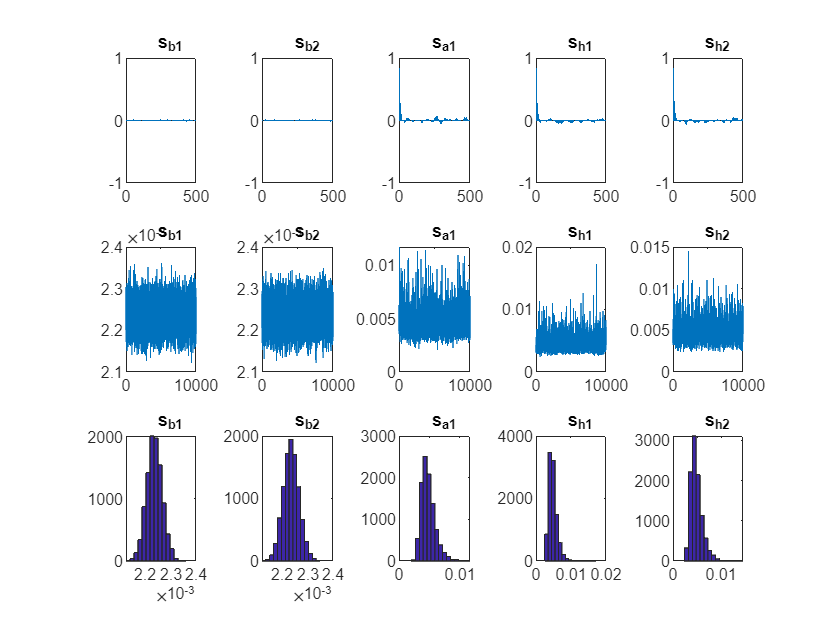

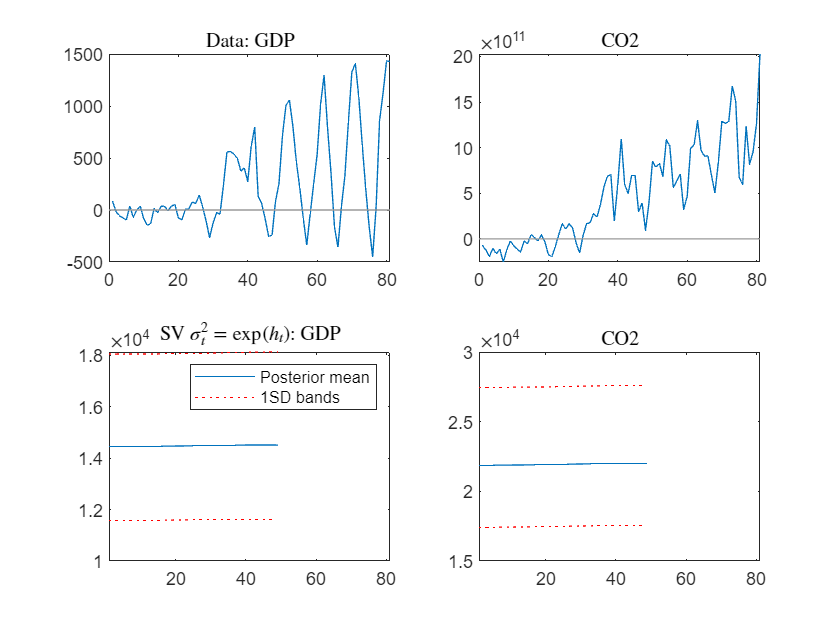

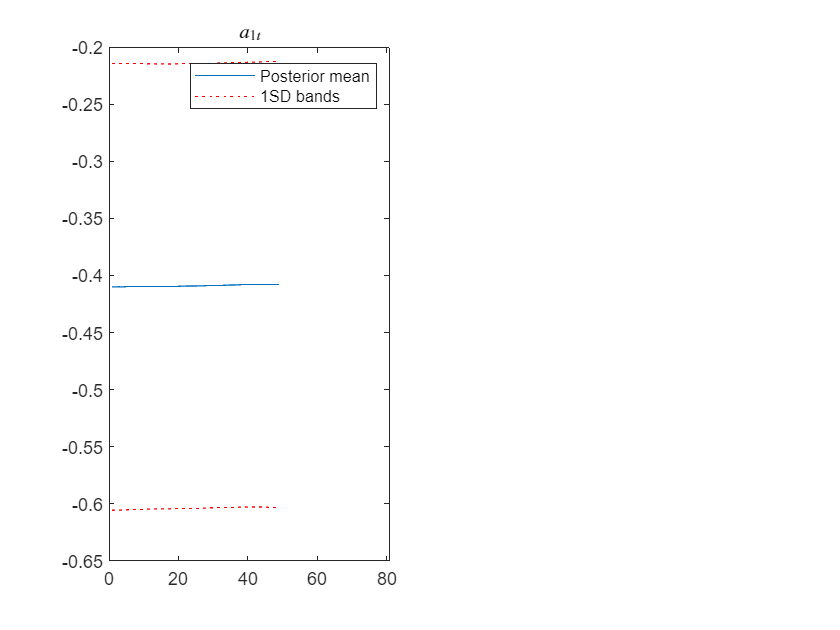

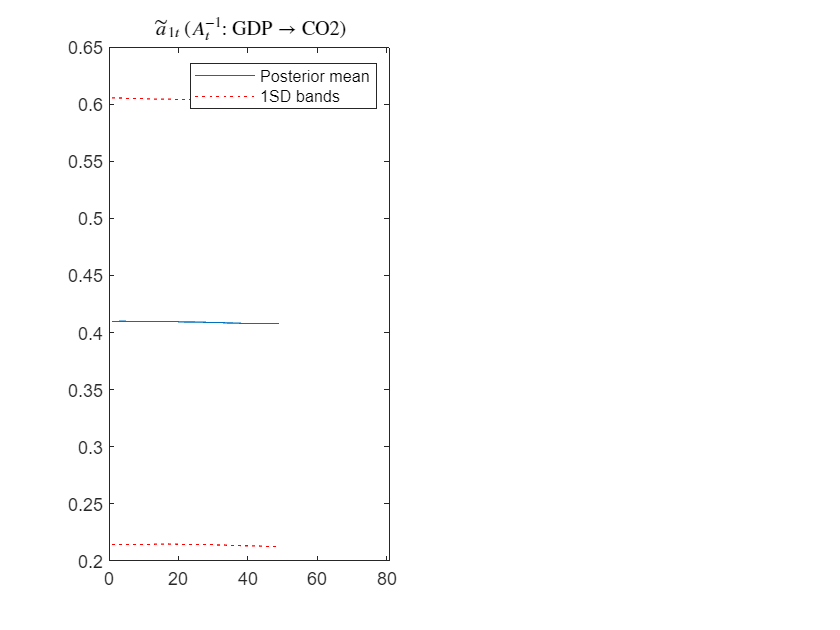



Ranseed: 1
Time: 94.63



figure()
% xlswrite('tvpvar_test.xlsx', CHINA_data(1:end-2,:), 'Sheet1', 'A1');
my = CHINA_data(1:end-2,:);
nlag = 4;  
set_global_variables('data', my, asvar, nlag); 
set_global_variables('fastimp', 1);  % fast computing of response
[CHINACO2, CHINAGDP] = mote_carlo_simulation(10000, CHINA_CO2, CHINA_GDP, 3);  %Target set

Path to China Carbon Neutrality Target: **ONLY 0.25% success rate**


Iteration:
-1000 
0 
1000 
2000 
3000 
4000 
5000 
6000 
7000 
8000 
9000 
10000 


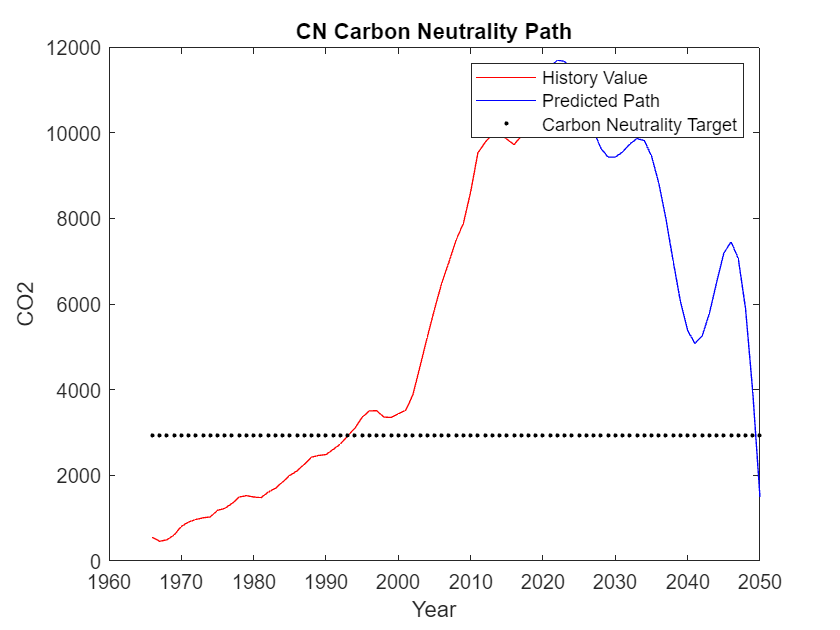

The probability to achieve neutrality goal：0.0026


figure()
my = CHINA_data(1:end-2,:);
nlag = 4;
set_global_variables('data', my, asvar, nlag);
set_global_variables('fastimp', 1);  % fast computing of response
[CHINACO2, CHINAGDP] = carbon_neutrality_path(10000, CHINA_CO2, CHINA_GDP, 3);  %Target set

## Deep Learning LSTM Regression: US Data

I applied LSTM model to US co2 data to simulate the path with deep learning techniques. **This method still presents a good level of fitness with RMSE is only around 5%**, although it lacks a certain level of interpretability from economics perspective. 

Result Graph:

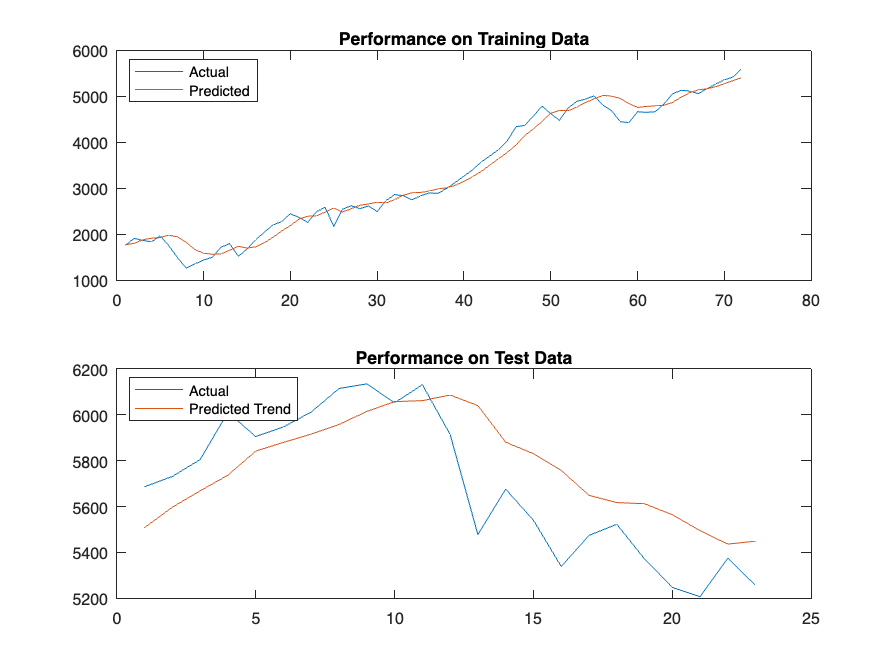

**Getting data: US_CO2 as data, Years as dates**

- changing data

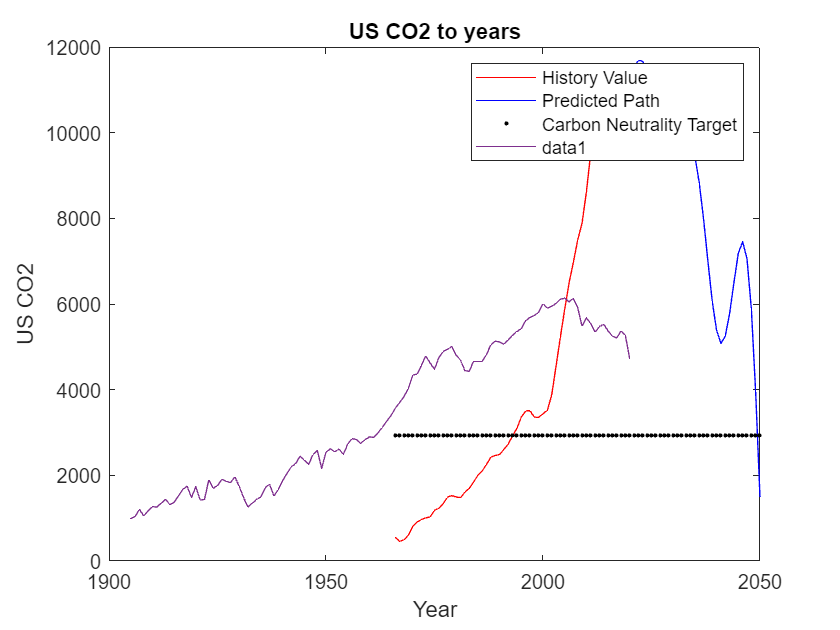

dates_year=Years(:,6:end);
data=US_CO2;
plot(dates_year,data)
hold on
title("US CO2 to years")
ylabel("US CO2")
hold off

From the plot, there are several missing values. The arrow points out some missing values. The next step is to clean the data and preprocess the data for training.

**Data Cleaning**

Remove the missing values. Adjust data into sequences with lags

if sum(ismissing(data))
    xRaw = rmmissing(data); % remove missing values
else
    xRaw = data;
end

dates_year = dates_year(~ismissing(data));

Create indices for partitioning data into training set and testing set

% nTest = sum(year(dates) == year(dates(end))); % Number of test days: Last year
% nTrain = numel(xRaw) - (nTest+1);

nTest=uint8(numel(dates_year)*0.2); %给更多的训练集：2-8
nTrain=numel(xRaw) - (nTest+1);
idxTrain = (1:nTrain)';
idxTest = (nTrain+1:numel(xRaw))';

datesTrain = dates_year(idxTrain);
datesTest = dates_year(idxTest);

Standardize data for both training and testing

[x1, mu1, sigma1] = standardizeByCol(xRaw(idxTrain));
x2 = (xRaw(idxTest) - repmat(mu1,nTest+1,1)) ./ repmat(sigma1,nTest+1,1); % standardize test data using training data mean and standard deviation
xNorm = [x1; x2];

Create a response variable

sequenceLength = 20;
Y = xNorm(sequenceLength+1:end-1,1);
nFeatures = size(xNorm,2); % num columns in data

Create lags

nrows = size(xNorm,1) + 1 - sequenceLength ;
for row = 1: nrows-1
    X{row} = xNorm(row:sequenceLength+row-1,:)';
end
X = X';
X = X(1:end-1,:);
% clear xRaw yRaw c d series xNorm nrows row

Partion data into training set and testing set

XTrain = X(1:end-nTest,:);
YTrain = Y(1:end-nTest,:);
XTest = X(end-nTest+1:end,:);
YTest = Y(end-nTest+1:end,:);

**Run LSTM networks**

Define LSTM layers. Build neural networks in [Deep Network Designer](https://www.mathworks.com/help/deeplearning/ref/deepnetworkdesigner-app.html).

layers = [sequenceInputLayer(nFeatures)
    lstmLayer(256, 'OutputMode', 'last')
    fullyConnectedLayer(1)
    regressionLayer];
deepNetworkDesigner(layerGraph(layers))

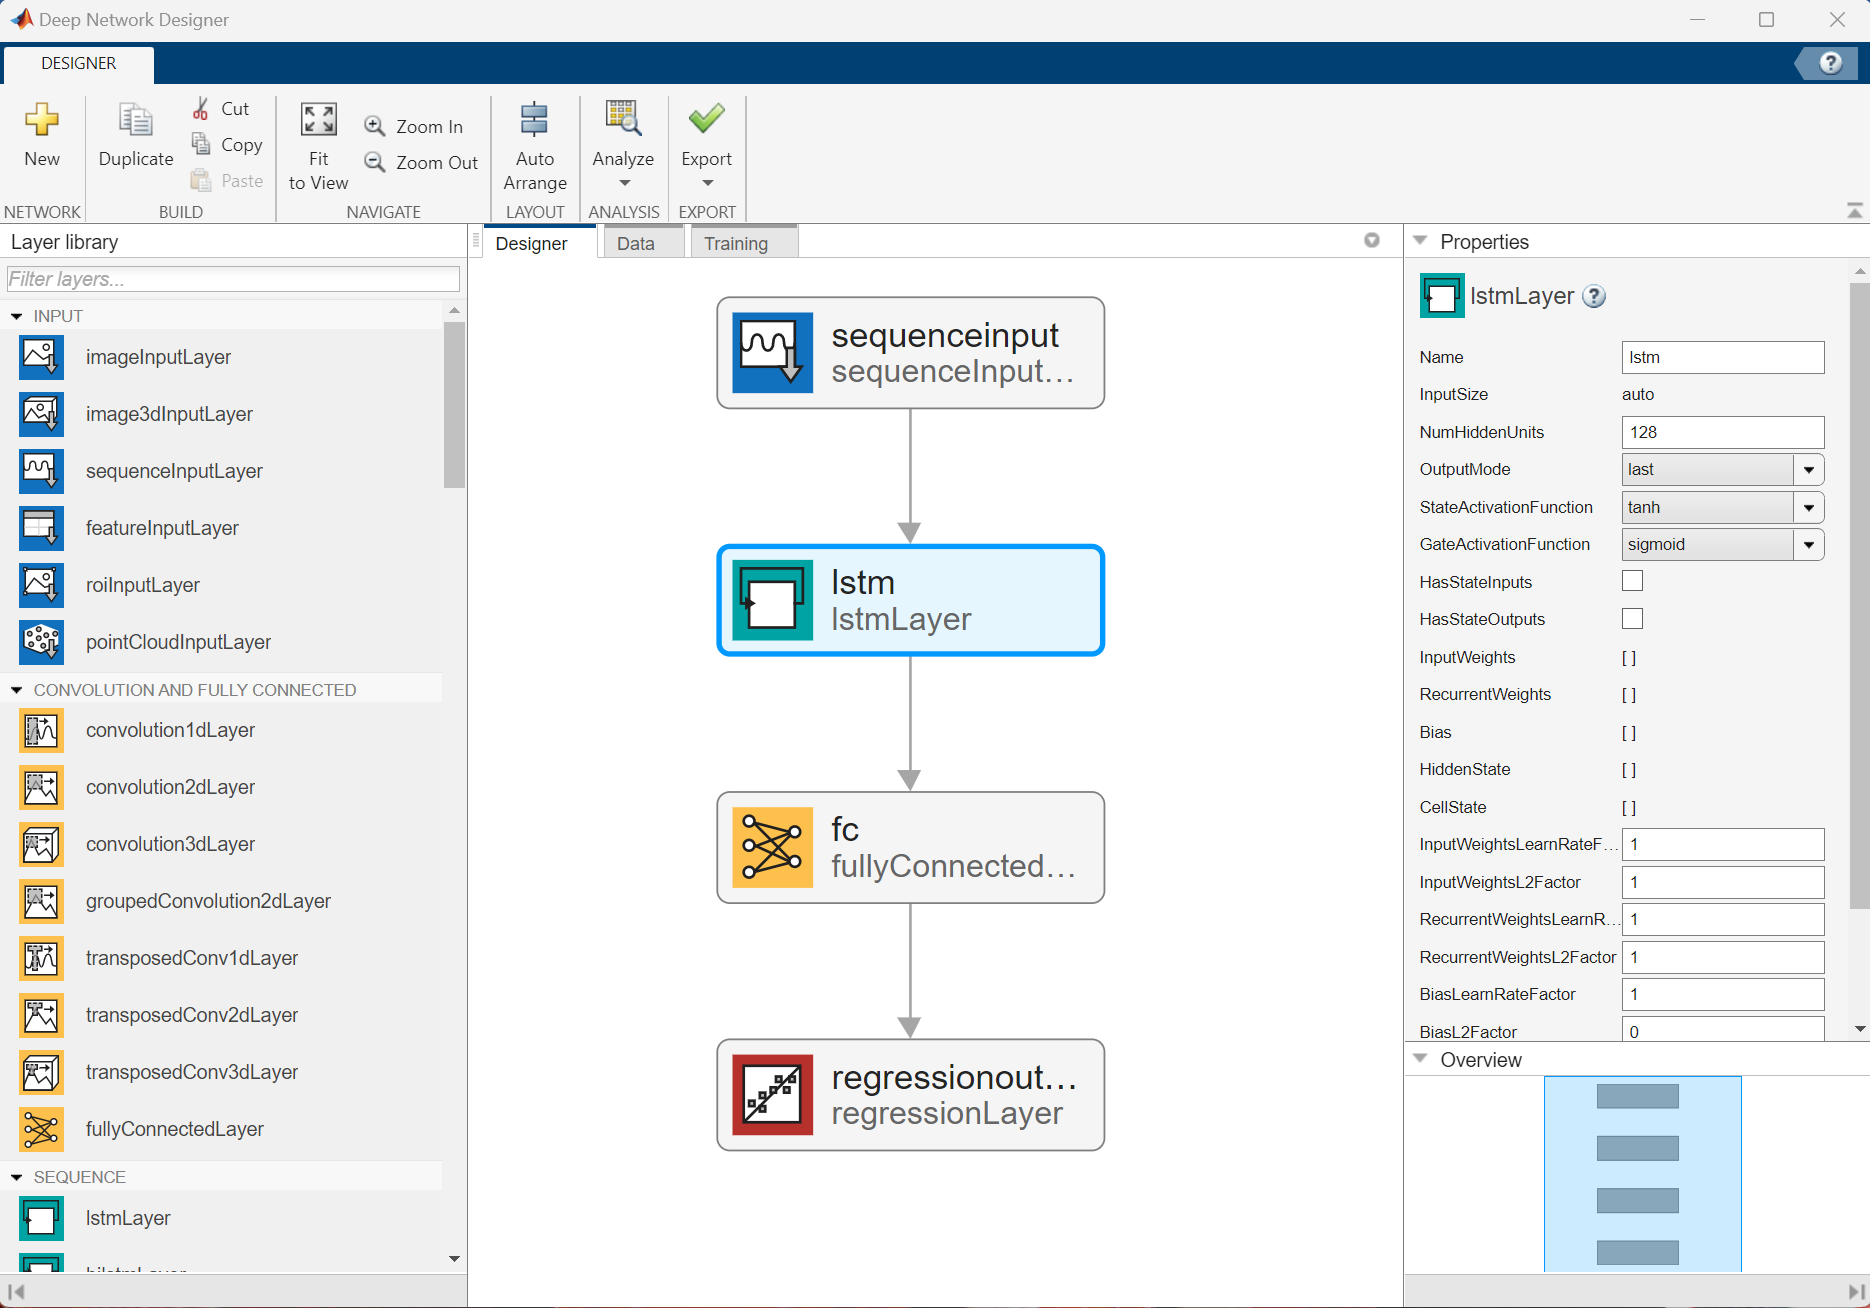

Set training options

miniBatchSize = 5;
% rng(100);
opts = trainingOptions('sgdm',...
    'Plots','training-progress', ...
    'LearnRateSchedule', 'piecewise', ...
    'shuffle', 'never',...
    'InitialLearnRate', 0.01,...
    'MiniBatchSize', miniBatchSize,...
    'MaxEpochs', 30); 
% GPU options

To avoid waiting for the training, load the pretrained network by setting the `doTraining` flag to `false`. To train the networks using [`analyzeNetwork`](https://www.mathworks.com/help/deeplearning/ref/analyzenetwork.html) (Deep Learning Toolbox), set the `doTraining` flag to `true`. The **Training Progress** window displays progress when `Plots` in `trainingOptions` is set as `training-progress`.

Training on single CPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:03 |         0.79 |          0.3 |          0.0100 |
|       4 |          50 |       00:00:07 |         0.08 |      2.9e-03 |          0.0100 |
|       8 |         100 |       00:00:08 |         0.31 |      4.8e-02 |          0.0100 |
|      11 |         150 |       00:00:10 |         0.20 |      2.0e-02 |          0.0010 |
|      15 |         200 |       00:00:12 |         0.15 |      1.1e-02 |          0.0010 |
|      18 |         250 |       00:00:13 |         0.24 |      2.8e-02 |          0.0010 |
|      22 |         300 |       00:00:15 |         0.08 |      2.8

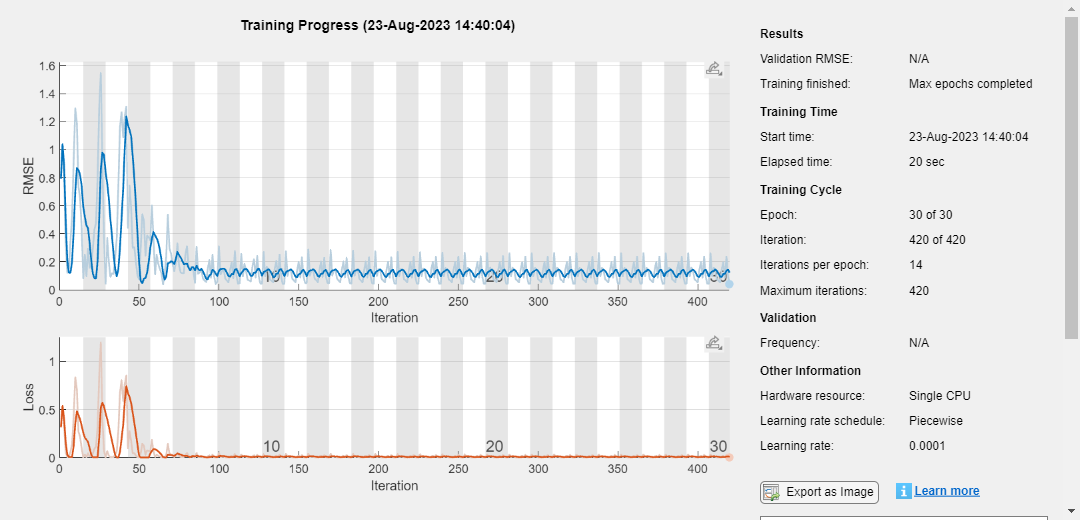

net =   SeriesNetwork with properties:

         Layers: [4×1 nnet.cnn.layer.Layer]
     InputNames: {'sequenceinput'}
    OutputNames: {'regressionoutput'}


doTraining = true;
if doTraining
    % Train the network.
    net = trainNetwork(XTrain, YTrain, layers, opts)
else
    % Load the pretrained network for the example.
    load("net.mat",'net');
end

**Forecast**

YpredTest = predict(net, XTest);
YpredTrain = predict(net, XTrain);

**Visualize the data**

Convert normalized data back using mean$\mu$ and standard deviation $\sigma$

predictTrain = YpredTrain(:)*sigma1 + mu1;
actualTrain = YTrain(:)*sigma1 + mu1;
predictTest = YpredTest(:)*sigma1 + mu1;
actualTest = YTest(:)*sigma1 + mu1;

Plot the performance on both training and testing data separately. Compute their root of mean squared error (RMSE).

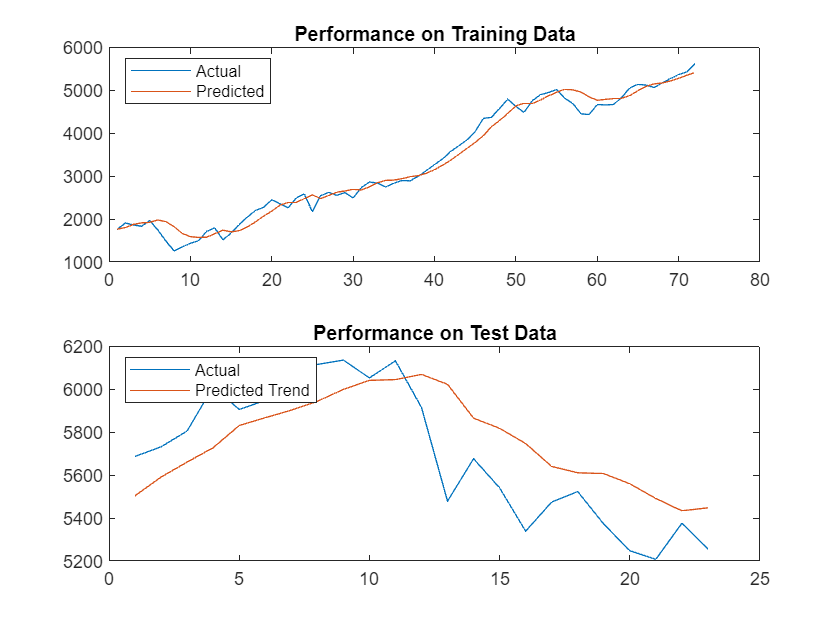

figure
subplot(2,2,[1 2])
plot(actualTrain);
hold on;
plot(predictTrain);
hold off;
title('Performance on Training Data');
legend('Actual', 'Predicted','Location','northwest');
subplot(2,2,[3 4])
plot(actualTest);
hold on;
plot(predictTest);
hold off;
title('Performance on Test Data');
legend('Actual', 'Predicted Trend','Location','northwest');

RMSE_Train = sqrt(mean((actualTrain - predictTrain).^2))

RMSE_Train = single
197.5481

new_R_train=RMSE_Train/mean(actualTrain)

new_R_train = single
0.0595

RMSE_Test = sqrt(mean((actualTest - predictTest).^2))

RMSE_Test = single
222.5549

new_R_Test=RMSE_Test/mean(actualTest)

new_R_Test = single
0.0391

## Reference

[1]

*United Nations Framework Convention on Climate Change message from the President of the United States transmitting the United Nations Framework Convention on Climate Change, adopted May 9, 1992, by the resumed fifth session of the intergovernmental negotiating committee for a Framework Convention on Climate Change (“convention”), and signed on behalf of the United States, at the United Nations Conference on Environment and Development (UNCED) in Rio De Janeiro on June 12, 1992*. Washington: U.S. G.P.O, 1992.

[2]

I. Goodfellow, Y. Bengio, A. Courville, and I. Goodfellow, *Deep learning : das umfassende Handbuch : Grundlagen, aktuelle Verfahren und Algorithmen, neue Forschungsansätze*, 1st ed. Frechen: mitp Verlags GmbH & Co, 2018.

[3]

P. Friedlingstein *et al.*, “Global Carbon Budget 2022,” vol. 14, no. 11, pp. 4811–4900, 2022, doi: 10.5194/essd-14-4811-2022.

[4]

J. Nakajima, “Time-Varying Parameter VAR Model with Stochastic Volatility: An Overview of Methodology and Empirical Applications.” Federal Reserve Bank of St Louis, St. Louis, 2011.

[5]

“STATEMENT ON THE ‘CLIMATE CHANGE 2023: SYNTHESIS REPORT,’” 2023.

[6]

S. Mujeeb and N. Javaid, “Deep learning based carbon emissions forecasting and renewable energy’s impact quantification,” vol. 17, no. 4, pp. 873–884, 2023, doi: 10.1049/rpg2.12641.

[7]

J. A. Leggett, *A U.S.-centric chronology of the United Nations Framework Convention on Climate Change*. Washington, D.C: Congressional Research Service, 2018.

**Supporting Functions**

Standardize data by column $\tilde{X}=\frac{X-\mu}{\sigma}$.

function [X, mu, sigma] = standardizeByCol(X)
n = size(X,1);
mu = mean(X);
sigma = std(X);
X = (X - repmat(mu,n,1)) ./ repmat(sigma,n,1);
end

% Function to update the map based on the rollbar values
function updateMap()
    countryIndex = round(countryRollbar.Value);
    yearIndex = round(yearRollbar.Value);
    
    % Get the carbon emission values for the selected country and year
    carbonEmissions = eval([countries{countryIndex} '_CO2']); % Evaluate the corresponding variable
    
    % Clear the previous map
    clf;
    
    % Plot the map
    geoshow(circleHandle, 'MarkerSize', carbonEmissions(yearIndex));
    
    % Set appropriate title and labels
    title(sprintf('Carbon Emissions in %s - Year %d', countries{countryIndex}, Years(yearIndex)));
end

Copyright 2023 The MathWorks, Inc.